%Loading the Data
load data\mnist_train.csv

%Showing n-th Image
n = 1;
img_matrix = reshape(mnist_train(n, 2:end), [28 28])'

img_matrix =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     3    18    18    18   126   136   175    26   166   255   247   1

digit = mnist_train(n, 1)

digit = 5

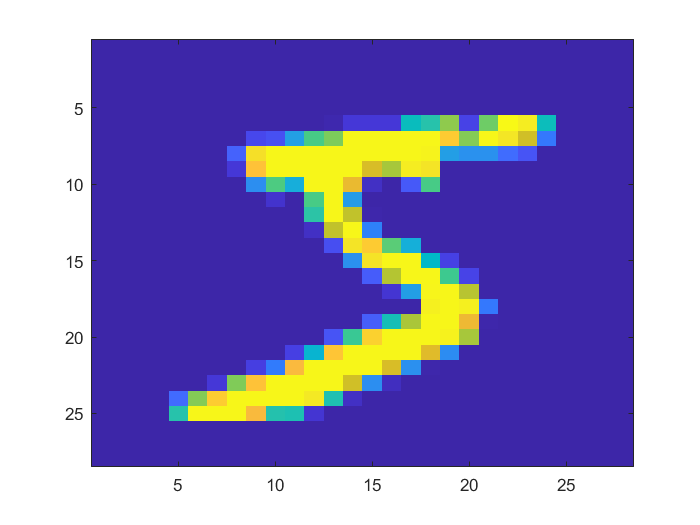

image(img_matrix)

%One Hot Encoding of Labels
labels = mnist_train(:, 1);
labels = categorical(labels);
labels = onehotencode(labels, 2);

%Building the Neural Network
layers = [784 16 16 10]

layers =    784    16    16    10



weights = {};
for i = 2:length(layers)
    weights = {weights{:}, -1 + 2.*rand(layers(i-1), layers(i))'};
end

%weights = {-1 + 2.*rand(neurons_input, neurons_hl(1))', -1 + 2.*rand(neurons_hl(1), neurons_hl(2))', -1 + 2.*rand(neurons_hl(2), neurons_output)'}
%weights{1}(1,1)

biases = {};
for i = 2:length(layers)
    biases = {biases{:}, -1 + 2.*rand(layers(i),1)};
end

%biases = {rand(neurons_hl(1), 1), rand(neurons_hl(2), 1), rand(neurons_output, 1)}
%biases{1}(1)

C = [];
for iter = 1:10000
%iter = n

iter = 1


%Setting Activations
activations = {1/256 * mnist_train(iter, 2:end)'}

activations = 1×1 cell array
    {784×1 double}


for i = 2:length(layers)
    activations = {activations{:}, zeros(layers(i), 1)};
end

%activations = {1/256 * mnist_train(n, 2:end)', zeros(neurons_hl(1), 1), zeros(neurons_hl(2), 1), zeros(neurons_output, 1)}
%activations{2}(1)


%Pass Forward
for l = 2:length(layers)
    activations{l} = sigmoid(weights{l-1} * activations{l-1} + biases{l-1});
end

%Error Measure
C(end+1) = (activations{end}-labels(iter,:)')'*(activations{end}-labels(iter,:)');

%Backprop in last layer
l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

l = 4

dzw = activations{l-1}

dzw =     0.0061
    0.0060
    0.0058
    0.0059
    0.0059
    0.0058
    0.0058
    0.0057
    0.0059
    0.0058


dzw =     0.0061
    0.0060
    0.0058
    0.0059
    0.0059
    0.0058
    0.0058
    0.0057
    0.0058
    0.0058


dzw =     0.0061
    0.0060
    0.0058
    0.0059
    0.0059
    0.0058
    0.0058
    0.0057
    0.0058
    0.0058


dzw = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0059
    0.0058
    0.0058
    0.0057
    0.0058
    0.0058


dzw = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0059
    0.0057
    0.0058
    0.0057
    0.0058
    0.0058


dzw = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0059
    0.0057
    0.0058
    0.0057
    0.0058
    0.0058


dzw = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0057
    0.0058
    0.0058


dzw = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0057
    0.0058
    0.0058


dzw = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0057
    0.0058
    0.0058


dzw = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0058


dzw = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dzw = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dzw = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dzw = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dzw = 16×1
    0.0060
    0.0059
    0.0057
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dzw = 16×1
    0.0060
    0.0059
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dzw = 16×1
    0.0060
    0.0059
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dzw = 16×1
    0.0060
    0.0059
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dzw = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dzw = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dzw = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0056
    0.0057
    0.0056
    0.0057
    0.0057


dzw = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dzw = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dzw = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dzw = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dzw = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0057


dzw = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dzw = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dzw = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dzw = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dzw = 16×1
    0.0059
    0.0058
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dzw = 16×1
    0.0059
    0.0058
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dzw = 16×1
    0.0059
    0.0058
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0055
    0.0056
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dzw = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dzw = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dzw = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dzw = 16×1
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dzw = 16×1
    0.0058
    0.0057
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dzw = 16×1
    0.0058
    0.0057
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dzw = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dzw = 16×1
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dzw = 16×1
    0.0057
    0.0056
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dzw = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dzw = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0053


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dzw = 16×1
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dzw = 16×1
    0.0056
    0.0055
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dzw = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dzw = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0052
    0.0053
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0052
    0.0052
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0052
    0.0052
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0052
    0.0052
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0052
    0.0052
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0052
    0.0052
    0.0052
    0.0053
    0.0053


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0052
    0.0052
    0.0052
    0.0053
    0.0052


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0052
    0.0052
    0.0052
    0.0053
    0.0052


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0052
    0.0052
    0.0051
    0.0053
    0.0052


dzw = 16×1
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0052
    0.0052
    0.0051
    0.0053
    0.0052


dzw = 16×1
    0.0055
    0.0053
    0.0052
    0.0053
    0.0053
    0.0052
    0.0052
    0.0051
    0.0053
    0.0052


dzw = 16×1
    0.0055
    0.0053
    0.0052
    0.0053
    0.0053
    0.0052
    0.0052
    0.0051
    0.0053
    0.0052


daz = dsigmoid(weights{l-1} * activations{l-1} + biases{l-1})

daz =     0.0554
    0.0574
    0.0611
    0.0566
    0.0586
    0.0579
    0.0555
    0.0580
    0.0586
    0.0584


daz =     0.0553
    0.0573
    0.0610
    0.0566
    0.0586
    0.0579
    0.0554
    0.0579
    0.0585
    0.0584


daz =     0.0553
    0.0573
    0.0610
    0.0566
    0.0585
    0.0579
    0.0554
    0.0579
    0.0585
    0.0583


daz = 10×1
    0.0553
    0.0573
    0.0610
    0.0565
    0.0585
    0.0578
    0.0554
    0.0579
    0.0585
    0.0583


daz = 10×1
    0.0553
    0.0572
    0.0609
    0.0565
    0.0585
    0.0578
    0.0553
    0.0578
    0.0584
    0.0582


daz = 10×1
    0.0552
    0.0572
    0.0609
    0.0565
    0.0584
    0.0578
    0.0553
    0.0578
    0.0584
    0.0582


daz = 10×1
    0.0552
    0.0572
    0.0608
    0.0564
    0.0584
    0.0577
    0.0553
    0.0578
    0.0584
    0.0582


daz = 10×1
    0.0552
    0.0571
    0.0608
    0.0564
    0.0584
    0.0577
    0.0553
    0.0577
    0.0583
    0.0581


daz = 10×1
    0.0551
    0.0571
    0.0608
    0.0564
    0.0583
    0.0577
    0.0552
    0.0577
    0.0583
    0.0581


daz = 10×1
    0.0551
    0.0571
    0.0607
    0.0563
    0.0583
    0.0576
    0.0552
    0.0577
    0.0582
    0.0581


daz = 10×1
    0.0551
    0.0570
    0.0607
    0.0563
    0.0583
    0.0576
    0.0552
    0.0576
    0.0582
    0.0580


daz = 10×1
    0.0550
    0.0570
    0.0606
    0.0563
    0.0582
    0.0576
    0.0551
    0.0576
    0.0582
    0.0580


daz = 10×1
    0.0550
    0.0570
    0.0606
    0.0562
    0.0582
    0.0575
    0.0551
    0.0576
    0.0581
    0.0580


daz = 10×1
    0.0550
    0.0569
    0.0606
    0.0562
    0.0582
    0.0575
    0.0551
    0.0575
    0.0581
    0.0579


daz = 10×1
    0.0549
    0.0569
    0.0605
    0.0562
    0.0581
    0.0575
    0.0550
    0.0575
    0.0581
    0.0579


daz = 10×1
    0.0549
    0.0569
    0.0605
    0.0561
    0.0581
    0.0574
    0.0550
    0.0575
    0.0580
    0.0579


daz = 10×1
    0.0549
    0.0568
    0.0604
    0.0561
    0.0580
    0.0574
    0.0550
    0.0574
    0.0580
    0.0578


daz = 10×1
    0.0549
    0.0568
    0.0604
    0.0561
    0.0580
    0.0573
    0.0549
    0.0574
    0.0580
    0.0578


daz = 10×1
    0.0548
    0.0568
    0.0604
    0.0560
    0.0580
    0.0573
    0.0549
    0.0574
    0.0579
    0.0578


daz = 10×1
    0.0548
    0.0567
    0.0603
    0.0560
    0.0579
    0.0573
    0.0549
    0.0573
    0.0579
    0.0577


daz = 10×1
    0.0548
    0.0567
    0.0603
    0.0560
    0.0579
    0.0572
    0.0549
    0.0573
    0.0579
    0.0577


daz = 10×1
    0.0547
    0.0567
    0.0603
    0.0560
    0.0579
    0.0572
    0.0548
    0.0573
    0.0578
    0.0577


daz = 10×1
    0.0547
    0.0566
    0.0602
    0.0559
    0.0578
    0.0572
    0.0548
    0.0572
    0.0578
    0.0576


daz = 10×1
    0.0547
    0.0566
    0.0602
    0.0559
    0.0578
    0.0571
    0.0548
    0.0572
    0.0578
    0.0576


daz = 10×1
    0.0546
    0.0566
    0.0601
    0.0559
    0.0578
    0.0571
    0.0547
    0.0572
    0.0577
    0.0576


daz = 10×1
    0.0546
    0.0565
    0.0601
    0.0558
    0.0577
    0.0571
    0.0547
    0.0571
    0.0577
    0.0575


daz = 10×1
    0.0546
    0.0565
    0.0601
    0.0558
    0.0577
    0.0570
    0.0547
    0.0571
    0.0576
    0.0575


daz = 10×1
    0.0545
    0.0565
    0.0600
    0.0558
    0.0577
    0.0570
    0.0546
    0.0571
    0.0576
    0.0575


daz = 10×1
    0.0545
    0.0564
    0.0600
    0.0557
    0.0576
    0.0570
    0.0546
    0.0570
    0.0576
    0.0574


daz = 10×1
    0.0545
    0.0564
    0.0599
    0.0557
    0.0576
    0.0569
    0.0546
    0.0570
    0.0575
    0.0574


daz = 10×1
    0.0545
    0.0564
    0.0599
    0.0557
    0.0576
    0.0569
    0.0546
    0.0570
    0.0575
    0.0574


daz = 10×1
    0.0544
    0.0564
    0.0599
    0.0556
    0.0575
    0.0569
    0.0545
    0.0569
    0.0575
    0.0573


daz = 10×1
    0.0544
    0.0563
    0.0598
    0.0556
    0.0575
    0.0568
    0.0545
    0.0569
    0.0574
    0.0573


daz = 10×1
    0.0544
    0.0563
    0.0598
    0.0556
    0.0575
    0.0568
    0.0545
    0.0569
    0.0574
    0.0573


daz = 10×1
    0.0543
    0.0563
    0.0598
    0.0555
    0.0574
    0.0568
    0.0544
    0.0568
    0.0574
    0.0572


daz = 10×1
    0.0543
    0.0562
    0.0597
    0.0555
    0.0574
    0.0567
    0.0544
    0.0568
    0.0573
    0.0572


daz = 10×1
    0.0543
    0.0562
    0.0597
    0.0555
    0.0574
    0.0567
    0.0544
    0.0568
    0.0573
    0.0572


daz = 10×1
    0.0542
    0.0562
    0.0596
    0.0554
    0.0573
    0.0567
    0.0544
    0.0567
    0.0573
    0.0571


daz = 10×1
    0.0542
    0.0561
    0.0596
    0.0554
    0.0573
    0.0566
    0.0543
    0.0567
    0.0572
    0.0571


daz = 10×1
    0.0542
    0.0561
    0.0596
    0.0554
    0.0573
    0.0566
    0.0543
    0.0567
    0.0572
    0.0571


daz = 10×1
    0.0542
    0.0561
    0.0595
    0.0554
    0.0572
    0.0566
    0.0543
    0.0566
    0.0572
    0.0570


daz = 10×1
    0.0541
    0.0560
    0.0595
    0.0553
    0.0572
    0.0565
    0.0542
    0.0566
    0.0571
    0.0570


daz = 10×1
    0.0541
    0.0560
    0.0595
    0.0553
    0.0572
    0.0565
    0.0542
    0.0566
    0.0571
    0.0570


daz = 10×1
    0.0541
    0.0560
    0.0594
    0.0553
    0.0571
    0.0565
    0.0542
    0.0565
    0.0571
    0.0569


daz = 10×1
    0.0540
    0.0559
    0.0594
    0.0552
    0.0571
    0.0564
    0.0541
    0.0565
    0.0570
    0.0569


daz = 10×1
    0.0540
    0.0559
    0.0594
    0.0552
    0.0571
    0.0564
    0.0541
    0.0565
    0.0570
    0.0569


daz = 10×1
    0.0540
    0.0559
    0.0593
    0.0552
    0.0570
    0.0564
    0.0541
    0.0564
    0.0570
    0.0568


daz = 10×1
    0.0540
    0.0558
    0.0593
    0.0551
    0.0570
    0.0563
    0.0541
    0.0564
    0.0569
    0.0568


daz = 10×1
    0.0539
    0.0558
    0.0592
    0.0551
    0.0570
    0.0563
    0.0540
    0.0564
    0.0569
    0.0568


daz = 10×1
    0.0539
    0.0558
    0.0592
    0.0551
    0.0569
    0.0563
    0.0540
    0.0563
    0.0569
    0.0567


daz = 10×1
    0.0539
    0.0557
    0.0592
    0.0550
    0.0569
    0.0563
    0.0540
    0.0563
    0.0568
    0.0567


daz = 10×1
    0.0538
    0.0557
    0.0591
    0.0550
    0.0569
    0.0562
    0.0539
    0.0563
    0.0568
    0.0567


daz = 10×1
    0.0538
    0.0557
    0.0591
    0.0550
    0.0568
    0.0562
    0.0539
    0.0562
    0.0568
    0.0566


daz = 10×1
    0.0538
    0.0557
    0.0591
    0.0550
    0.0568
    0.0562
    0.0539
    0.0562
    0.0567
    0.0566


daz = 10×1
    0.0538
    0.0556
    0.0590
    0.0549
    0.0568
    0.0561
    0.0539
    0.0562
    0.0567
    0.0566


daz = 10×1
    0.0537
    0.0556
    0.0590
    0.0549
    0.0567
    0.0561
    0.0538
    0.0561
    0.0567
    0.0565


daz = 10×1
    0.0537
    0.0556
    0.0590
    0.0549
    0.0567
    0.0561
    0.0538
    0.0561
    0.0566
    0.0565


daz = 10×1
    0.0537
    0.0555
    0.0589
    0.0548
    0.0567
    0.0560
    0.0538
    0.0561
    0.0566
    0.0565


daz = 10×1
    0.0536
    0.0555
    0.0589
    0.0548
    0.0566
    0.0560
    0.0537
    0.0560
    0.0566
    0.0564


daz = 10×1
    0.0536
    0.0555
    0.0588
    0.0548
    0.0566
    0.0560
    0.0537
    0.0560
    0.0565
    0.0564


daz = 10×1
    0.0536
    0.0554
    0.0588
    0.0547
    0.0566
    0.0559
    0.0537
    0.0560
    0.0565
    0.0564


daz = 10×1
    0.0536
    0.0554
    0.0588
    0.0547
    0.0565
    0.0559
    0.0537
    0.0560
    0.0565
    0.0563


daz = 10×1
    0.0535
    0.0554
    0.0587
    0.0547
    0.0565
    0.0559
    0.0536
    0.0559
    0.0564
    0.0563


daz = 10×1
    0.0535
    0.0553
    0.0587
    0.0547
    0.0565
    0.0558
    0.0536
    0.0559
    0.0564
    0.0563


daz = 10×1
    0.0535
    0.0553
    0.0587
    0.0546
    0.0564
    0.0558
    0.0536
    0.0559
    0.0564
    0.0562


daz = 10×1
    0.0534
    0.0553
    0.0586
    0.0546
    0.0564
    0.0558
    0.0536
    0.0558
    0.0563
    0.0562


daz = 10×1
    0.0534
    0.0553
    0.0586
    0.0546
    0.0564
    0.0557
    0.0535
    0.0558
    0.0563
    0.0562


daz = 10×1
    0.0534
    0.0552
    0.0586
    0.0545
    0.0564
    0.0557
    0.0535
    0.0558
    0.0563
    0.0561


daz = 10×1
    0.0534
    0.0552
    0.0585
    0.0545
    0.0563
    0.0557
    0.0535
    0.0557
    0.0562
    0.0561


daz = 10×1
    0.0533
    0.0552
    0.0585
    0.0545
    0.0563
    0.0556
    0.0534
    0.0557
    0.0562
    0.0561


daz = 10×1
    0.0533
    0.0551
    0.0585
    0.0544
    0.0563
    0.0556
    0.0534
    0.0557
    0.0562
    0.0561


daz = 10×1
    0.0533
    0.0551
    0.0584
    0.0544
    0.0562
    0.0556
    0.0534
    0.0556
    0.0561
    0.0560


daz = 10×1
    0.0532
    0.0551
    0.0584
    0.0544
    0.0562
    0.0556
    0.0534
    0.0556
    0.0561
    0.0560


daz = 10×1
    0.0532
    0.0550
    0.0583
    0.0544
    0.0562
    0.0555
    0.0533
    0.0556
    0.0561
    0.0560


daz = 10×1
    0.0532
    0.0550
    0.0583
    0.0543
    0.0561
    0.0555
    0.0533
    0.0555
    0.0560
    0.0559


daz = 10×1
    0.0532
    0.0550
    0.0583
    0.0543
    0.0561
    0.0555
    0.0533
    0.0555
    0.0560
    0.0559


daz = 10×1
    0.0531
    0.0550
    0.0582
    0.0543
    0.0561
    0.0554
    0.0532
    0.0555
    0.0560
    0.0559


daz = 10×1
    0.0531
    0.0549
    0.0582
    0.0542
    0.0560
    0.0554
    0.0532
    0.0555
    0.0559
    0.0558


daz = 10×1
    0.0531
    0.0549
    0.0582
    0.0542
    0.0560
    0.0554
    0.0532
    0.0554
    0.0559
    0.0558


daz = 10×1
    0.0530
    0.0549
    0.0581
    0.0542
    0.0560
    0.0553
    0.0532
    0.0554
    0.0559
    0.0558


daz = 10×1
    0.0530
    0.0548
    0.0581
    0.0541
    0.0559
    0.0553
    0.0531
    0.0554
    0.0558
    0.0557


daz = 10×1
    0.0530
    0.0548
    0.0581
    0.0541
    0.0559
    0.0553
    0.0531
    0.0553
    0.0558
    0.0557


daz = 10×1
    0.0530
    0.0548
    0.0580
    0.0541
    0.0559
    0.0552
    0.0531
    0.0553
    0.0558
    0.0557


daz = 10×1
    0.0529
    0.0547
    0.0580
    0.0541
    0.0558
    0.0552
    0.0531
    0.0553
    0.0558
    0.0556


daz = 10×1
    0.0529
    0.0547
    0.0580
    0.0540
    0.0558
    0.0552
    0.0530
    0.0552
    0.0557
    0.0556


daz = 10×1
    0.0529
    0.0547
    0.0579
    0.0540
    0.0558
    0.0552
    0.0530
    0.0552
    0.0557
    0.0556


daz = 10×1
    0.0529
    0.0547
    0.0579
    0.0540
    0.0558
    0.0551
    0.0530
    0.0552
    0.0557
    0.0556


daz = 10×1
    0.0528
    0.0546
    0.0579
    0.0539
    0.0557
    0.0551
    0.0529
    0.0551
    0.0556
    0.0555


daz = 10×1
    0.0528
    0.0546
    0.0578
    0.0539
    0.0557
    0.0551
    0.0529
    0.0551
    0.0556
    0.0555


daz = 10×1
    0.0528
    0.0546
    0.0578
    0.0539
    0.0557
    0.0550
    0.0529
    0.0551
    0.0556
    0.0555


daz = 10×1
    0.0527
    0.0545
    0.0578
    0.0539
    0.0556
    0.0550
    0.0529
    0.0551
    0.0555
    0.0554


daz = 10×1
    0.0527
    0.0545
    0.0577
    0.0538
    0.0556
    0.0550
    0.0528
    0.0550
    0.0555
    0.0554


daz = 10×1
    0.0527
    0.0545
    0.0577
    0.0538
    0.0556
    0.0549
    0.0528
    0.0550
    0.0555
    0.0554


daz = 10×1
    0.0527
    0.0544
    0.0577
    0.0538
    0.0555
    0.0549
    0.0528
    0.0550
    0.0554
    0.0553


daz = 10×1
    0.0526
    0.0544
    0.0576
    0.0537
    0.0555
    0.0549
    0.0528
    0.0549
    0.0554
    0.0553


daz = 10×1
    0.0526
    0.0544
    0.0576
    0.0537
    0.0555
    0.0549
    0.0527
    0.0549
    0.0554
    0.0553


daz = 10×1
    0.0526
    0.0544
    0.0576
    0.0537
    0.0554
    0.0548
    0.0527
    0.0549
    0.0553
    0.0552


daz = 10×1
    0.0526
    0.0543
    0.0575
    0.0537
    0.0554
    0.0548
    0.0527
    0.0548
    0.0553
    0.0552


daz = 10×1
    0.0525
    0.0543
    0.0575
    0.0536
    0.0554
    0.0548
    0.0526
    0.0548
    0.0553
    0.0552


daz = 10×1
    0.0525
    0.0543
    0.0575
    0.0536
    0.0554
    0.0547
    0.0526
    0.0548
    0.0553
    0.0552


dCa = 2 * (activations{end}-labels(iter,:)')

dCa =     0.1177
    0.1222
    0.1307
    0.1205
    0.1250
   -0.1235
    0.1179
    0.1236
    0.1250
    0.1245


dCa =     0.1176
    0.1221
    0.1306
    0.1205
    0.1250
   -0.1234
    0.1178
    0.1235
    0.1249
    0.1244


dCa =     0.1175
    0.1221
    0.1305
    0.1204
    0.1249
   -0.1233
    0.1177
    0.1234
    0.1248
    0.1244


dCa = 10×1
    0.1175
    0.1220
    0.1304
    0.1203
    0.1248
   -0.1233
    0.1177
    0.1233
    0.1247
    0.1243


dCa = 10×1
    0.1174
    0.1219
    0.1303
    0.1202
    0.1247
   -0.1232
    0.1176
    0.1233
    0.1246
    0.1242


dCa = 10×1
    0.1173
    0.1218
    0.1302
    0.1202
    0.1246
   -0.1231
    0.1175
    0.1232
    0.1245
    0.1241


dCa = 10×1
    0.1173
    0.1218
    0.1301
    0.1201
    0.1246
   -0.1230
    0.1175
    0.1231
    0.1245
    0.1240


dCa = 10×1
    0.1172
    0.1217
    0.1300
    0.1200
    0.1245
   -0.1229
    0.1174
    0.1230
    0.1244
    0.1240


dCa = 10×1
    0.1171
    0.1216
    0.1300
    0.1199
    0.1244
   -0.1229
    0.1173
    0.1230
    0.1243
    0.1239


dCa = 10×1
    0.1170
    0.1215
    0.1299
    0.1199
    0.1243
   -0.1228
    0.1173
    0.1229
    0.1242
    0.1238


dCa = 10×1
    0.1170
    0.1215
    0.1298
    0.1198
    0.1242
   -0.1227
    0.1172
    0.1228
    0.1241
    0.1237


dCa = 10×1
    0.1169
    0.1214
    0.1297
    0.1197
    0.1242
   -0.1226
    0.1171
    0.1227
    0.1240
    0.1236


dCa = 10×1
    0.1168
    0.1213
    0.1296
    0.1196
    0.1241
   -0.1225
    0.1171
    0.1226
    0.1240
    0.1236


dCa = 10×1
    0.1168
    0.1212
    0.1295
    0.1196
    0.1240
   -0.1225
    0.1170
    0.1226
    0.1239
    0.1235


dCa = 10×1
    0.1167
    0.1212
    0.1294
    0.1195
    0.1239
   -0.1224
    0.1169
    0.1225
    0.1238
    0.1234


dCa = 10×1
    0.1166
    0.1211
    0.1293
    0.1194
    0.1238
   -0.1223
    0.1168
    0.1224
    0.1237
    0.1233


dCa = 10×1
    0.1166
    0.1210
    0.1292
    0.1194
    0.1238
   -0.1222
    0.1168
    0.1223
    0.1236
    0.1233


dCa = 10×1
    0.1165
    0.1209
    0.1291
    0.1193
    0.1237
   -0.1222
    0.1167
    0.1223
    0.1236
    0.1232


dCa = 10×1
    0.1164
    0.1209
    0.1291
    0.1192
    0.1236
   -0.1221
    0.1166
    0.1222
    0.1235
    0.1231


dCa = 10×1
    0.1164
    0.1208
    0.1290
    0.1191
    0.1235
   -0.1220
    0.1166
    0.1221
    0.1234
    0.1230


dCa = 10×1
    0.1163
    0.1207
    0.1289
    0.1191
    0.1234
   -0.1219
    0.1165
    0.1220
    0.1233
    0.1229


dCa = 10×1
    0.1162
    0.1206
    0.1288
    0.1190
    0.1234
   -0.1218
    0.1164
    0.1219
    0.1232
    0.1229


dCa = 10×1
    0.1161
    0.1206
    0.1287
    0.1189
    0.1233
   -0.1218
    0.1164
    0.1219
    0.1232
    0.1228


dCa = 10×1
    0.1161
    0.1205
    0.1286
    0.1188
    0.1232
   -0.1217
    0.1163
    0.1218
    0.1231
    0.1227


dCa = 10×1
    0.1160
    0.1204
    0.1285
    0.1188
    0.1231
   -0.1216
    0.1162
    0.1217
    0.1230
    0.1226


dCa = 10×1
    0.1159
    0.1203
    0.1284
    0.1187
    0.1230
   -0.1215
    0.1162
    0.1216
    0.1229
    0.1226


dCa = 10×1
    0.1159
    0.1203
    0.1284
    0.1186
    0.1230
   -0.1215
    0.1161
    0.1216
    0.1228
    0.1225


dCa = 10×1
    0.1158
    0.1202
    0.1283
    0.1186
    0.1229
   -0.1214
    0.1160
    0.1215
    0.1228
    0.1224


dCa = 10×1
    0.1157
    0.1201
    0.1282
    0.1185
    0.1228
   -0.1213
    0.1160
    0.1214
    0.1227
    0.1223


dCa = 10×1
    0.1157
    0.1200
    0.1281
    0.1184
    0.1227
   -0.1212
    0.1159
    0.1213
    0.1226
    0.1222


dCa = 10×1
    0.1156
    0.1200
    0.1280
    0.1183
    0.1227
   -0.1212
    0.1158
    0.1213
    0.1225
    0.1222


dCa = 10×1
    0.1155
    0.1199
    0.1279
    0.1183
    0.1226
   -0.1211
    0.1158
    0.1212
    0.1224
    0.1221


dCa = 10×1
    0.1155
    0.1198
    0.1278
    0.1182
    0.1225
   -0.1210
    0.1157
    0.1211
    0.1224
    0.1220


dCa = 10×1
    0.1154
    0.1197
    0.1278
    0.1181
    0.1224
   -0.1209
    0.1156
    0.1210
    0.1223
    0.1219


dCa = 10×1
    0.1153
    0.1197
    0.1277
    0.1180
    0.1224
   -0.1209
    0.1156
    0.1210
    0.1222
    0.1219


dCa = 10×1
    0.1153
    0.1196
    0.1276
    0.1180
    0.1223
   -0.1208
    0.1155
    0.1209
    0.1221
    0.1218


dCa = 10×1
    0.1152
    0.1195
    0.1275
    0.1179
    0.1222
   -0.1207
    0.1154
    0.1208
    0.1221
    0.1217


dCa = 10×1
    0.1151
    0.1195
    0.1274
    0.1178
    0.1221
   -0.1206
    0.1154
    0.1207
    0.1220
    0.1216


dCa = 10×1
    0.1151
    0.1194
    0.1273
    0.1178
    0.1220
   -0.1206
    0.1153
    0.1207
    0.1219
    0.1216


dCa = 10×1
    0.1150
    0.1193
    0.1272
    0.1177
    0.1220
   -0.1205
    0.1152
    0.1206
    0.1218
    0.1215


dCa = 10×1
    0.1149
    0.1192
    0.1272
    0.1176
    0.1219
   -0.1204
    0.1152
    0.1205
    0.1217
    0.1214


dCa = 10×1
    0.1149
    0.1192
    0.1271
    0.1176
    0.1218
   -0.1203
    0.1151
    0.1204
    0.1217
    0.1213


dCa = 10×1
    0.1148
    0.1191
    0.1270
    0.1175
    0.1217
   -0.1203
    0.1150
    0.1204
    0.1216
    0.1213


dCa = 10×1
    0.1147
    0.1190
    0.1269
    0.1174
    0.1217
   -0.1202
    0.1150
    0.1203
    0.1215
    0.1212


dCa = 10×1
    0.1147
    0.1189
    0.1268
    0.1173
    0.1216
   -0.1201
    0.1149
    0.1202
    0.1214
    0.1211


dCa = 10×1
    0.1146
    0.1189
    0.1267
    0.1173
    0.1215
   -0.1200
    0.1148
    0.1201
    0.1214
    0.1210


dCa = 10×1
    0.1145
    0.1188
    0.1266
    0.1172
    0.1214
   -0.1200
    0.1148
    0.1201
    0.1213
    0.1210


dCa = 10×1
    0.1145
    0.1187
    0.1266
    0.1171
    0.1214
   -0.1199
    0.1147
    0.1200
    0.1212
    0.1209


dCa = 10×1
    0.1144
    0.1187
    0.1265
    0.1171
    0.1213
   -0.1198
    0.1146
    0.1199
    0.1211
    0.1208


dCa = 10×1
    0.1143
    0.1186
    0.1264
    0.1170
    0.1212
   -0.1197
    0.1146
    0.1198
    0.1210
    0.1207


dCa = 10×1
    0.1143
    0.1185
    0.1263
    0.1169
    0.1211
   -0.1197
    0.1145
    0.1198
    0.1210
    0.1207


dCa = 10×1
    0.1142
    0.1185
    0.1262
    0.1169
    0.1211
   -0.1196
    0.1144
    0.1197
    0.1209
    0.1206


dCa = 10×1
    0.1141
    0.1184
    0.1261
    0.1168
    0.1210
   -0.1195
    0.1144
    0.1196
    0.1208
    0.1205


dCa = 10×1
    0.1141
    0.1183
    0.1261
    0.1167
    0.1209
   -0.1194
    0.1143
    0.1196
    0.1207
    0.1204


dCa = 10×1
    0.1140
    0.1182
    0.1260
    0.1167
    0.1208
   -0.1194
    0.1143
    0.1195
    0.1207
    0.1204


dCa = 10×1
    0.1139
    0.1182
    0.1259
    0.1166
    0.1208
   -0.1193
    0.1142
    0.1194
    0.1206
    0.1203


dCa = 10×1
    0.1139
    0.1181
    0.1258
    0.1165
    0.1207
   -0.1192
    0.1141
    0.1193
    0.1205
    0.1202


dCa = 10×1
    0.1138
    0.1180
    0.1257
    0.1164
    0.1206
   -0.1192
    0.1141
    0.1193
    0.1204
    0.1201


dCa = 10×1
    0.1137
    0.1180
    0.1257
    0.1164
    0.1206
   -0.1191
    0.1140
    0.1192
    0.1204
    0.1201


dCa = 10×1
    0.1137
    0.1179
    0.1256
    0.1163
    0.1205
   -0.1190
    0.1139
    0.1191
    0.1203
    0.1200


dCa = 10×1
    0.1136
    0.1178
    0.1255
    0.1162
    0.1204
   -0.1189
    0.1139
    0.1191
    0.1202
    0.1199


dCa = 10×1
    0.1135
    0.1177
    0.1254
    0.1162
    0.1203
   -0.1189
    0.1138
    0.1190
    0.1201
    0.1199


dCa = 10×1
    0.1135
    0.1177
    0.1253
    0.1161
    0.1203
   -0.1188
    0.1137
    0.1189
    0.1201
    0.1198


dCa = 10×1
    0.1134
    0.1176
    0.1252
    0.1160
    0.1202
   -0.1187
    0.1137
    0.1188
    0.1200
    0.1197


dCa = 10×1
    0.1134
    0.1175
    0.1252
    0.1160
    0.1201
   -0.1186
    0.1136
    0.1188
    0.1199
    0.1196


dCa = 10×1
    0.1133
    0.1175
    0.1251
    0.1159
    0.1200
   -0.1186
    0.1135
    0.1187
    0.1198
    0.1196


dCa = 10×1
    0.1132
    0.1174
    0.1250
    0.1158
    0.1200
   -0.1185
    0.1135
    0.1186
    0.1198
    0.1195


dCa = 10×1
    0.1132
    0.1173
    0.1249
    0.1158
    0.1199
   -0.1184
    0.1134
    0.1186
    0.1197
    0.1194


dCa = 10×1
    0.1131
    0.1173
    0.1248
    0.1157
    0.1198
   -0.1184
    0.1134
    0.1185
    0.1196
    0.1193


dCa = 10×1
    0.1130
    0.1172
    0.1248
    0.1156
    0.1197
   -0.1183
    0.1133
    0.1184
    0.1195
    0.1193


dCa = 10×1
    0.1130
    0.1171
    0.1247
    0.1156
    0.1197
   -0.1182
    0.1132
    0.1183
    0.1195
    0.1192


dCa = 10×1
    0.1129
    0.1171
    0.1246
    0.1155
    0.1196
   -0.1182
    0.1132
    0.1183
    0.1194
    0.1191


dCa = 10×1
    0.1128
    0.1170
    0.1245
    0.1154
    0.1195
   -0.1181
    0.1131
    0.1182
    0.1193
    0.1191


dCa = 10×1
    0.1128
    0.1169
    0.1244
    0.1154
    0.1195
   -0.1180
    0.1130
    0.1181
    0.1193
    0.1190


dCa = 10×1
    0.1127
    0.1169
    0.1244
    0.1153
    0.1194
   -0.1179
    0.1130
    0.1181
    0.1192
    0.1189


dCa = 10×1
    0.1127
    0.1168
    0.1243
    0.1152
    0.1193
   -0.1179
    0.1129
    0.1180
    0.1191
    0.1189


dCa = 10×1
    0.1126
    0.1167
    0.1242
    0.1152
    0.1192
   -0.1178
    0.1129
    0.1179
    0.1190
    0.1188


dCa = 10×1
    0.1125
    0.1166
    0.1241
    0.1151
    0.1192
   -0.1177
    0.1128
    0.1178
    0.1190
    0.1187


dCa = 10×1
    0.1125
    0.1166
    0.1240
    0.1150
    0.1191
   -0.1177
    0.1127
    0.1178
    0.1189
    0.1186


dCa = 10×1
    0.1124
    0.1165
    0.1240
    0.1150
    0.1190
   -0.1176
    0.1127
    0.1177
    0.1188
    0.1186


dCa = 10×1
    0.1123
    0.1164
    0.1239
    0.1149
    0.1190
   -0.1175
    0.1126
    0.1176
    0.1187
    0.1185


dCa = 10×1
    0.1123
    0.1164
    0.1238
    0.1148
    0.1189
   -0.1174
    0.1125
    0.1176
    0.1187
    0.1184


dCa = 10×1
    0.1122
    0.1163
    0.1237
    0.1148
    0.1188
   -0.1174
    0.1125
    0.1175
    0.1186
    0.1184


dCa = 10×1
    0.1122
    0.1162
    0.1236
    0.1147
    0.1187
   -0.1173
    0.1124
    0.1174
    0.1185
    0.1183


dCa = 10×1
    0.1121
    0.1162
    0.1236
    0.1146
    0.1187
   -0.1172
    0.1124
    0.1174
    0.1185
    0.1182


dCa = 10×1
    0.1120
    0.1161
    0.1235
    0.1146
    0.1186
   -0.1172
    0.1123
    0.1173
    0.1184
    0.1181


dCa = 10×1
    0.1120
    0.1160
    0.1234
    0.1145
    0.1185
   -0.1171
    0.1122
    0.1172
    0.1183
    0.1181


dCa = 10×1
    0.1119
    0.1160
    0.1233
    0.1144
    0.1185
   -0.1170
    0.1122
    0.1172
    0.1182
    0.1180


dCa = 10×1
    0.1118
    0.1159
    0.1233
    0.1144
    0.1184
   -0.1170
    0.1121
    0.1171
    0.1182
    0.1179


dCa = 10×1
    0.1118
    0.1158
    0.1232
    0.1143
    0.1183
   -0.1169
    0.1121
    0.1170
    0.1181
    0.1179


dCa = 10×1
    0.1117
    0.1158
    0.1231
    0.1142
    0.1183
   -0.1168
    0.1120
    0.1170
    0.1180
    0.1178


dCa = 10×1
    0.1117
    0.1157
    0.1230
    0.1142
    0.1182
   -0.1168
    0.1119
    0.1169
    0.1180
    0.1177


dCa = 10×1
    0.1116
    0.1156
    0.1229
    0.1141
    0.1181
   -0.1167
    0.1119
    0.1168
    0.1179
    0.1177


dCa = 10×1
    0.1115
    0.1156
    0.1229
    0.1141
    0.1180
   -0.1166
    0.1118
    0.1167
    0.1178
    0.1176


dCa = 10×1
    0.1115
    0.1155
    0.1228
    0.1140
    0.1180
   -0.1166
    0.1118
    0.1167
    0.1177
    0.1175


dCa = 10×1
    0.1114
    0.1154
    0.1227
    0.1139
    0.1179
   -0.1165
    0.1117
    0.1166
    0.1177
    0.1175


dCa = 10×1
    0.1114
    0.1154
    0.1226
    0.1139
    0.1178
   -0.1164
    0.1116
    0.1165
    0.1176
    0.1174


dCa = 10×1
    0.1113
    0.1153
    0.1226
    0.1138
    0.1178
   -0.1163
    0.1116
    0.1165
    0.1175
    0.1173


dCa = 10×1
    0.1112
    0.1152
    0.1225
    0.1137
    0.1177
   -0.1163
    0.1115
    0.1164
    0.1175
    0.1173


dCa = 10×1
    0.1112
    0.1152
    0.1224
    0.1137
    0.1176
   -0.1162
    0.1114
    0.1163
    0.1174
    0.1172



dCw_l = (dzw * (daz .* dCa)')'

dCw_l = 	1.0e+-4 *

    0.3987    0.3889    0.3807    0.3876    0.3839    0.3763    0.3770    0.3719    0.3816    0.3789    0.3838    0.3701    0.3742    0.3908    0.3869    0.3988
    0.4290    0.4185    0.4096    0.4171    0.4130    0.4049    0.4057    0.4002    0.4105    0.4077    0.4129    0.3982    0.4026    0.4205    0.4163    0.4291
    0.4882    0.4762    0.4662    0.4747    0.4700    0.4608    0.4616    0.4554    0.4672    0.4640    0.4699    0.4531    0.4582    0.4785    0.4737    0.4883
    0.4176    0.4074    0.3988    0.4061    0.4021    0.3942    0.3949    0.3896    0.3997    0.3969    0.4020    0.3876    0.3920    0.4094    0.4053    0.4177
    0.4483    0.4373    0.4281    0.4359    0.4317    0.4232    0.4240    0.4182    0.4291    0.4261    0.4316    0.4161    0.4208    0.4395    0.4351    0.4484
   -0.4377   -0.4270   -0.4180   -0.4256   -0.4214   -0.4131   -0.4139   -0.4083   -0.4189   -0.4160   -0.4213   -0.4063   -0.4108   -0.4290   -0.4248   -0.4378
    0.4000    

dCw_l = 	1.0e+-4 *

    0.3977    0.3880    0.3798    0.3867    0.3830    0.3754    0.3761    0.3711    0.3807    0.3780    0.3829    0.3692    0.3733    0.3899    0.3860    0.3978
    0.4279    0.4175    0.4087    0.4161    0.4121    0.4040    0.4047    0.3992    0.4096    0.4067    0.4119    0.3973    0.4017    0.4195    0.4153    0.4280
    0.4869    0.4750    0.4650    0.4735    0.4689    0.4596    0.4605    0.4543    0.4660    0.4628    0.4687    0.4520    0.4571    0.4773    0.4726    0.4870
    0.4166    0.4064    0.3978    0.4051    0.4012    0.3933    0.3940    0.3887    0.3987    0.3960    0.4010    0.3867    0.3911    0.4084    0.4043    0.4167
    0.4472    0.4363    0.4271    0.4348    0.4306    0.4221    0.4229    0.4172    0.4280    0.4251    0.4305    0.4151    0.4198    0.4384    0.4340    0.4473
   -0.4366   -0.4260   -0.4170   -0.4245   -0.4204   -0.4122   -0.4129   -0.4073   -0.4179   -0.4150   -0.4203   -0.4053   -0.4098   -0.4280   -0.4237   -0.4367
    0.3991    

dCw_l = 	1.0e+-4 *

    0.3968    0.3871    0.3789    0.3858    0.3821    0.3746    0.3753    0.3702    0.3798    0.3772    0.3820    0.3684    0.3725    0.3890    0.3851    0.3969
    0.4269    0.4165    0.4077    0.4151    0.4111    0.4030    0.4038    0.3983    0.4086    0.4058    0.4110    0.3963    0.4007    0.4185    0.4143    0.4270
    0.4857    0.4738    0.4638    0.4723    0.4677    0.4585    0.4594    0.4531    0.4649    0.4617    0.4676    0.4509    0.4559    0.4761    0.4714    0.4858
    0.4156    0.4055    0.3969    0.4041    0.4002    0.3923    0.3931    0.3878    0.3978    0.3950    0.4001    0.3858    0.3901    0.4074    0.4033    0.4157
    0.4461    0.4352    0.4260    0.4338    0.4296    0.4211    0.4219    0.4162    0.4270    0.4240    0.4295    0.4142    0.4188    0.4373    0.4330    0.4462
   -0.4355   -0.4249   -0.4160   -0.4235   -0.4194   -0.4112   -0.4119   -0.4064   -0.4169   -0.4140   -0.4193   -0.4044   -0.4089   -0.4270   -0.4227   -0.4357
    0.3981    

dCw_l = 10×16
	1.0e+-4 *

    0.3958    0.3862    0.3781    0.3849    0.3812    0.3737    0.3744    0.3694    0.3789    0.3763    0.3811    0.3675    0.3716    0.3880    0.3842    0.3959
    0.4258    0.4155    0.4067    0.4141    0.4101    0.4020    0.4028    0.3974    0.4076    0.4048    0.4100    0.3954    0.3998    0.4175    0.4133    0.4260
    0.4844    0.4726    0.4627    0.4711    0.4665    0.4574    0.4582    0.4520    0.4637    0.4605    0.4664    0.4498    0.4548    0.4749    0.4702    0.4846
    0.4146    0.4045    0.3960    0.4032    0.3993    0.3914    0.3921    0.3869    0.3969    0.3941    0.3992    0.3849    0.3892    0.4064    0.4024    0.4147
    0.4450    0.4342    0.4250    0.4327    0.4285    0.4201    0.4209    0.4152    0.4260    0.4230    0.4284    0.4132    0.4178    0.4362    0.4319    0.4451
   -0.4345   -0.4239   -0.4150   -0.4225   -0.4184   -0.4102   -0.4109   -0.4054   -0.4159   -0.4130   -0.4183   -0.4034   -0.4079   -0.4259   -0.4217   -0.4346
    0.39

dCw_l = 10×16
	1.0e+-4 *

    0.3949    0.3853    0.3772    0.3840    0.3803    0.3728    0.3735    0.3685    0.3780    0.3754    0.3802    0.3667    0.3708    0.3871    0.3833    0.3950
    0.4248    0.4145    0.4058    0.4131    0.4091    0.4011    0.4018    0.3964    0.4067    0.4039    0.4090    0.3945    0.3989    0.4165    0.4123    0.4249
    0.4832    0.4714    0.4615    0.4699    0.4654    0.4562    0.4571    0.4509    0.4625    0.4594    0.4652    0.4487    0.4537    0.4737    0.4690    0.4833
    0.4136    0.4035    0.3950    0.4022    0.3983    0.3905    0.3912    0.3860    0.3959    0.3932    0.3982    0.3840    0.3883    0.4055    0.4014    0.4137
    0.4439    0.4331    0.4240    0.4317    0.4275    0.4191    0.4199    0.4142    0.4249    0.4220    0.4274    0.4122    0.4168    0.4352    0.4309    0.4440
   -0.4334   -0.4229   -0.4140   -0.4215   -0.4174   -0.4092   -0.4100   -0.4044   -0.4149   -0.4120   -0.4173   -0.4024   -0.4069   -0.4249   -0.4207   -0.4335
    0.39

dCw_l = 10×16
	1.0e+-4 *

    0.3940    0.3844    0.3763    0.3831    0.3794    0.3720    0.3727    0.3677    0.3771    0.3745    0.3793    0.3658    0.3699    0.3862    0.3824    0.3941
    0.4238    0.4135    0.4048    0.4121    0.4082    0.4002    0.4009    0.3955    0.4057    0.4029    0.4080    0.3936    0.3979    0.4155    0.4113    0.4239
    0.4820    0.4703    0.4604    0.4687    0.4642    0.4551    0.4559    0.4498    0.4614    0.4582    0.4641    0.4476    0.4525    0.4725    0.4678    0.4821
    0.4126    0.4026    0.3941    0.4012    0.3974    0.3896    0.3903    0.3851    0.3950    0.3923    0.3973    0.3832    0.3874    0.4045    0.4005    0.4127
    0.4428    0.4321    0.4230    0.4306    0.4265    0.4181    0.4189    0.4133    0.4239    0.4210    0.4264    0.4112    0.4158    0.4341    0.4298    0.4429
   -0.4323   -0.4218   -0.4130   -0.4204   -0.4164   -0.4082   -0.4090   -0.4035   -0.4139   -0.4110   -0.4163   -0.4015   -0.4059   -0.4239   -0.4196   -0.4325
    0.39

dCw_l = 10×16
	1.0e+-4 *

    0.3930    0.3835    0.3754    0.3822    0.3785    0.3711    0.3718    0.3668    0.3763    0.3737    0.3784    0.3650    0.3691    0.3853    0.3815    0.3931
    0.4228    0.4125    0.4038    0.4112    0.4072    0.3992    0.4000    0.3946    0.4047    0.4020    0.4071    0.3926    0.3970    0.4145    0.4104    0.4229
    0.4807    0.4691    0.4592    0.4675    0.4630    0.4540    0.4548    0.4487    0.4602    0.4571    0.4629    0.4465    0.4514    0.4713    0.4666    0.4809
    0.4116    0.4016    0.3932    0.4003    0.3964    0.3887    0.3894    0.3842    0.3941    0.3913    0.3963    0.3823    0.3865    0.4035    0.3995    0.4117
    0.4417    0.4310    0.4220    0.4296    0.4255    0.4171    0.4179    0.4123    0.4229    0.4200    0.4253    0.4102    0.4148    0.4331    0.4288    0.4419
   -0.4313   -0.4208   -0.4120   -0.4194   -0.4154   -0.4073   -0.4080   -0.4025   -0.4129   -0.4101   -0.4153   -0.4005   -0.4050   -0.4228   -0.4186   -0.4314
    0.39

dCw_l = 10×16
	1.0e+-4 *

    0.3921    0.3826    0.3746    0.3813    0.3777    0.3703    0.3710    0.3660    0.3754    0.3728    0.3776    0.3642    0.3682    0.3844    0.3806    0.3922
    0.4217    0.4115    0.4029    0.4102    0.4062    0.3983    0.3990    0.3937    0.4038    0.4010    0.4061    0.3917    0.3961    0.4135    0.4094    0.4219
    0.4795    0.4679    0.4581    0.4664    0.4619    0.4528    0.4537    0.4476    0.4591    0.4560    0.4617    0.4454    0.4503    0.4701    0.4655    0.4797
    0.4106    0.4007    0.3923    0.3993    0.3955    0.3878    0.3885    0.3833    0.3931    0.3904    0.3954    0.3814    0.3856    0.4026    0.3986    0.4107
    0.4406    0.4300    0.4210    0.4286    0.4244    0.4161    0.4169    0.4113    0.4219    0.4190    0.4243    0.4093    0.4138    0.4320    0.4277    0.4408
   -0.4302   -0.4198   -0.4110   -0.4184   -0.4144   -0.4063   -0.4070   -0.4016   -0.4119   -0.4091   -0.4143   -0.3996   -0.4040   -0.4218   -0.4176   -0.4303
    0.39

dCw_l = 10×16
	1.0e+-4 *

    0.3912    0.3817    0.3737    0.3804    0.3768    0.3694    0.3701    0.3651    0.3745    0.3720    0.3767    0.3634    0.3674    0.3835    0.3797    0.3913
    0.4207    0.4105    0.4019    0.4092    0.4053    0.3973    0.3981    0.3927    0.4028    0.4001    0.4052    0.3908    0.3951    0.4125    0.4084    0.4208
    0.4783    0.4667    0.4569    0.4652    0.4607    0.4517    0.4526    0.4465    0.4580    0.4548    0.4606    0.4443    0.4492    0.4690    0.4643    0.4784
    0.4096    0.3997    0.3913    0.3984    0.3946    0.3869    0.3876    0.3824    0.3922    0.3895    0.3945    0.3805    0.3847    0.4016    0.3976    0.4097
    0.4396    0.4289    0.4199    0.4275    0.4234    0.4151    0.4159    0.4103    0.4209    0.4180    0.4233    0.4083    0.4128    0.4310    0.4267    0.4397
   -0.4292   -0.4188   -0.4100   -0.4174   -0.4134   -0.4053   -0.4061   -0.4006   -0.4109   -0.4081   -0.4133   -0.3987   -0.4031   -0.4208   -0.4166   -0.4293
    0.39

dCw_l = 10×16
	1.0e+-4 *

    0.3902    0.3808    0.3728    0.3796    0.3759    0.3686    0.3693    0.3643    0.3737    0.3711    0.3758    0.3625    0.3665    0.3826    0.3788    0.3904
    0.4197    0.4096    0.4010    0.4082    0.4043    0.3964    0.3972    0.3918    0.4019    0.3991    0.4042    0.3899    0.3942    0.4115    0.4075    0.4198
    0.4771    0.4656    0.4558    0.4640    0.4596    0.4506    0.4514    0.4454    0.4568    0.4537    0.4595    0.4432    0.4481    0.4678    0.4632    0.4772
    0.4086    0.3988    0.3904    0.3975    0.3936    0.3860    0.3867    0.3815    0.3913    0.3886    0.3935    0.3796    0.3838    0.4007    0.3967    0.4088
    0.4385    0.4279    0.4189    0.4265    0.4224    0.4142    0.4149    0.4094    0.4199    0.4170    0.4223    0.4073    0.4119    0.4299    0.4257    0.4386
   -0.4281   -0.4178   -0.4090   -0.4164   -0.4124   -0.4044   -0.4051   -0.3997   -0.4099   -0.4071   -0.4123   -0.3977   -0.4021   -0.4198   -0.4156   -0.4282
    0.39

dCw_l = 10×16
	1.0e+-4 *

    0.3893    0.3799    0.3720    0.3787    0.3750    0.3677    0.3684    0.3635    0.3728    0.3703    0.3749    0.3617    0.3657    0.3817    0.3780    0.3894
    0.4187    0.4086    0.4001    0.4073    0.4034    0.3955    0.3962    0.3909    0.4009    0.3982    0.4032    0.3890    0.3933    0.4105    0.4065    0.4188
    0.4759    0.4644    0.4547    0.4629    0.4584    0.4495    0.4503    0.4443    0.4557    0.4526    0.4583    0.4421    0.4470    0.4666    0.4620    0.4760
    0.4077    0.3978    0.3895    0.3965    0.3927    0.3851    0.3858    0.3806    0.3904    0.3877    0.3926    0.3787    0.3829    0.3997    0.3958    0.4078
    0.4374    0.4269    0.4179    0.4255    0.4214    0.4132    0.4139    0.4084    0.4189    0.4160    0.4213    0.4064    0.4109    0.4289    0.4247    0.4375
   -0.4271   -0.4168   -0.4081   -0.4154   -0.4114   -0.4034   -0.4042   -0.3987   -0.4090   -0.4062   -0.4113   -0.3968   -0.4012   -0.4188   -0.4146   -0.4272
    0.39

dCw_l = 10×16
	1.0e+-4 *

    0.3884    0.3790    0.3711    0.3778    0.3742    0.3669    0.3676    0.3627    0.3719    0.3694    0.3741    0.3609    0.3649    0.3808    0.3771    0.3885
    0.4177    0.4076    0.3991    0.4063    0.4024    0.3946    0.3953    0.3900    0.4000    0.3973    0.4023    0.3881    0.3924    0.4096    0.4055    0.4178
    0.4747    0.4632    0.4536    0.4617    0.4573    0.4484    0.4492    0.4432    0.4546    0.4515    0.4572    0.4410    0.4459    0.4654    0.4608    0.4748
    0.4067    0.3969    0.3886    0.3956    0.3918    0.3842    0.3849    0.3797    0.3895    0.3868    0.3917    0.3779    0.3820    0.3988    0.3948    0.4068
    0.4364    0.4258    0.4169    0.4244    0.4204    0.4122    0.4130    0.4074    0.4179    0.4150    0.4203    0.4054    0.4099    0.4279    0.4236    0.4365
   -0.4260   -0.4158   -0.4071   -0.4144   -0.4104   -0.4024   -0.4032   -0.3978   -0.4080   -0.4052   -0.4103   -0.3958   -0.4002   -0.4177   -0.4136   -0.4262
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3875    0.3782    0.3703    0.3769    0.3733    0.3661    0.3667    0.3618    0.3711    0.3686    0.3732    0.3601    0.3640    0.3800    0.3762    0.3876
    0.4167    0.4067    0.3982    0.4053    0.4015    0.3936    0.3944    0.3891    0.3991    0.3963    0.4013    0.3872    0.3915    0.4086    0.4046    0.4168
    0.4735    0.4621    0.4524    0.4606    0.4562    0.4473    0.4481    0.4421    0.4534    0.4503    0.4560    0.4400    0.4448    0.4643    0.4597    0.4736
    0.4057    0.3960    0.3877    0.3947    0.3909    0.3833    0.3840    0.3789    0.3885    0.3859    0.3908    0.3770    0.3812    0.3978    0.3939    0.4058
    0.4353    0.4248    0.4160    0.4234    0.4194    0.4112    0.4120    0.4065    0.4169    0.4140    0.4193    0.4045    0.4089    0.4268    0.4226    0.4354
   -0.4250   -0.4148   -0.4061   -0.4134   -0.4095   -0.4015   -0.4022   -0.3969   -0.4070   -0.4042   -0.4093   -0.3949   -0.3993   -0.4167   -0.4126   -0.4251
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3866    0.3773    0.3694    0.3761    0.3725    0.3652    0.3659    0.3610    0.3702    0.3677    0.3724    0.3592    0.3632    0.3791    0.3753    0.3867
    0.4157    0.4057    0.3972    0.4044    0.4005    0.3927    0.3935    0.3882    0.3981    0.3954    0.4004    0.3863    0.3906    0.4076    0.4036    0.4158
    0.4723    0.4609    0.4513    0.4594    0.4550    0.4462    0.4470    0.4411    0.4523    0.4492    0.4549    0.4389    0.4437    0.4631    0.4586    0.4724
    0.4048    0.3950    0.3868    0.3937    0.3900    0.3824    0.3831    0.3780    0.3876    0.3850    0.3899    0.3761    0.3803    0.3969    0.3930    0.4049
    0.4342    0.4238    0.4150    0.4224    0.4184    0.4102    0.4110    0.4055    0.4159    0.4130    0.4183    0.4035    0.4080    0.4258    0.4216    0.4344
   -0.4240   -0.4138   -0.4052   -0.4124   -0.4085   -0.4005   -0.4013   -0.3959   -0.4060   -0.4033   -0.4084   -0.3940   -0.3983   -0.4157   -0.4116   -0.4241
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3857    0.3764    0.3686    0.3752    0.3716    0.3644    0.3651    0.3602    0.3694    0.3669    0.3715    0.3584    0.3624    0.3782    0.3745    0.3858
    0.4147    0.4047    0.3963    0.4034    0.3996    0.3918    0.3925    0.3873    0.3972    0.3945    0.3995    0.3854    0.3896    0.4067    0.4027    0.4148
    0.4711    0.4598    0.4502    0.4583    0.4539    0.4451    0.4459    0.4400    0.4512    0.4481    0.4538    0.4378    0.4426    0.4620    0.4574    0.4712
    0.4038    0.3941    0.3859    0.3928    0.3891    0.3815    0.3822    0.3771    0.3867    0.3841    0.3890    0.3753    0.3794    0.3960    0.3921    0.4039
    0.4332    0.4228    0.4140    0.4214    0.4174    0.4093    0.4100    0.4046    0.4149    0.4121    0.4173    0.4026    0.4070    0.4248    0.4206    0.4333
   -0.4229   -0.4128   -0.4042   -0.4114   -0.4075   -0.3996   -0.4003   -0.3950   -0.4051   -0.4023   -0.4074   -0.3931   -0.3974   -0.4147   -0.4107   -0.4231
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3848    0.3755    0.3677    0.3743    0.3707    0.3636    0.3642    0.3594    0.3685    0.3660    0.3706    0.3576    0.3615    0.3773    0.3736    0.3849
    0.4137    0.4038    0.3954    0.4025    0.3986    0.3909    0.3916    0.3864    0.3963    0.3936    0.3985    0.3845    0.3887    0.4057    0.4017    0.4138
    0.4699    0.4586    0.4491    0.4571    0.4528    0.4440    0.4448    0.4389    0.4501    0.4470    0.4527    0.4368    0.4416    0.4608    0.4563    0.4701
    0.4028    0.3932    0.3850    0.3919    0.3881    0.3806    0.3813    0.3762    0.3858    0.3832    0.3880    0.3744    0.3785    0.3950    0.3911    0.4029
    0.4321    0.4218    0.4130    0.4204    0.4164    0.4083    0.4091    0.4036    0.4139    0.4111    0.4163    0.4016    0.4060    0.4238    0.4196    0.4323
   -0.4219   -0.4118   -0.4032   -0.4105   -0.4065   -0.3987   -0.3994   -0.3941   -0.4041   -0.4014   -0.4064   -0.3922   -0.3965   -0.4137   -0.4097   -0.4220
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3839    0.3747    0.3669    0.3735    0.3699    0.3627    0.3634    0.3586    0.3677    0.3652    0.3698    0.3568    0.3607    0.3764    0.3728    0.3840
    0.4127    0.4028    0.3945    0.4015    0.3977    0.3900    0.3907    0.3855    0.3953    0.3926    0.3976    0.3836    0.3878    0.4047    0.4008    0.4128
    0.4687    0.4575    0.4480    0.4560    0.4517    0.4429    0.4437    0.4378    0.4490    0.4459    0.4515    0.4357    0.4405    0.4597    0.4552    0.4689
    0.4019    0.3922    0.3841    0.3910    0.3872    0.3797    0.3804    0.3754    0.3849    0.3823    0.3871    0.3735    0.3776    0.3941    0.3902    0.4020
    0.4311    0.4208    0.4120    0.4194    0.4154    0.4073    0.4081    0.4027    0.4129    0.4101    0.4153    0.4007    0.4051    0.4227    0.4186    0.4312
   -0.4209   -0.4108   -0.4023   -0.4095   -0.4056   -0.3977   -0.3985   -0.3932   -0.4032   -0.4004   -0.4055   -0.3912   -0.3955   -0.4127   -0.4087   -0.4210
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3830    0.3738    0.3660    0.3726    0.3690    0.3619    0.3626    0.3578    0.3669    0.3644    0.3689    0.3560    0.3599    0.3756    0.3719    0.3831
    0.4117    0.4019    0.3935    0.4006    0.3968    0.3891    0.3898    0.3846    0.3944    0.3917    0.3967    0.3828    0.3869    0.4038    0.3998    0.4119
    0.4676    0.4564    0.4469    0.4549    0.4506    0.4418    0.4427    0.4368    0.4479    0.4448    0.4504    0.4346    0.4394    0.4585    0.4540    0.4677
    0.4009    0.3913    0.3832    0.3901    0.3863    0.3789    0.3796    0.3745    0.3840    0.3814    0.3862    0.3727    0.3768    0.3932    0.3893    0.4010
    0.4300    0.4197    0.4110    0.4184    0.4144    0.4064    0.4071    0.4017    0.4119    0.4091    0.4143    0.3998    0.4041    0.4217    0.4176    0.4302
   -0.4199   -0.4098   -0.4013   -0.4085   -0.4046   -0.3968   -0.3975   -0.3922   -0.4022   -0.3995   -0.4045   -0.3903   -0.3946   -0.4118   -0.4077   -0.4200
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3821    0.3729    0.3652    0.3717    0.3682    0.3611    0.3618    0.3569    0.3660    0.3635    0.3681    0.3552    0.3591    0.3747    0.3710    0.3822
    0.4108    0.4009    0.3926    0.3996    0.3958    0.3882    0.3889    0.3837    0.3935    0.3908    0.3957    0.3819    0.3860    0.4028    0.3989    0.4109
    0.4664    0.4552    0.4458    0.4538    0.4494    0.4408    0.4416    0.4357    0.4468    0.4438    0.4493    0.4336    0.4383    0.4574    0.4529    0.4665
    0.4000    0.3904    0.3823    0.3891    0.3854    0.3780    0.3787    0.3737    0.3832    0.3806    0.3853    0.3718    0.3759    0.3922    0.3884    0.4001
    0.4290    0.4187    0.4101    0.4174    0.4134    0.4054    0.4062    0.4008    0.4110    0.4082    0.4133    0.3988    0.4032    0.4207    0.4166    0.4291
   -0.4189   -0.4089   -0.4004   -0.4075   -0.4037   -0.3959   -0.3966   -0.3913   -0.4013   -0.3985   -0.4035   -0.3894   -0.3937   -0.4108   -0.4068   -0.4190
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3812    0.3721    0.3644    0.3709    0.3674    0.3603    0.3609    0.3561    0.3652    0.3627    0.3673    0.3544    0.3583    0.3738    0.3702    0.3813
    0.4098    0.4000    0.3917    0.3987    0.3949    0.3873    0.3880    0.3829    0.3926    0.3899    0.3948    0.3810    0.3852    0.4019    0.3979    0.4099
    0.4652    0.4541    0.4447    0.4526    0.4483    0.4397    0.4405    0.4347    0.4457    0.4427    0.4482    0.4325    0.4373    0.4562    0.4518    0.4654
    0.3990    0.3895    0.3814    0.3882    0.3845    0.3771    0.3778    0.3728    0.3823    0.3797    0.3844    0.3710    0.3750    0.3913    0.3875    0.3991
    0.4280    0.4177    0.4091    0.4164    0.4124    0.4045    0.4052    0.3998    0.4100    0.4072    0.4123    0.3979    0.4022    0.4197    0.4156    0.4281
   -0.4179   -0.4079   -0.3994   -0.4066   -0.4027   -0.3949   -0.3957   -0.3904   -0.4003   -0.3976   -0.4026   -0.3885   -0.3927   -0.4098   -0.4058   -0.4180
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3803    0.3712    0.3636    0.3700    0.3665    0.3595    0.3601    0.3553    0.3643    0.3619    0.3664    0.3536    0.3575    0.3730    0.3693    0.3804
    0.4088    0.3991    0.3908    0.3978    0.3940    0.3864    0.3871    0.3820    0.3917    0.3890    0.3939    0.3801    0.3843    0.4009    0.3970    0.4089
    0.4641    0.4530    0.4436    0.4515    0.4472    0.4386    0.4394    0.4336    0.4446    0.4416    0.4471    0.4315    0.4362    0.4551    0.4507    0.4642
    0.3981    0.3886    0.3805    0.3873    0.3837    0.3763    0.3769    0.3720    0.3814    0.3788    0.3835    0.3701    0.3742    0.3904    0.3866    0.3982
    0.4269    0.4167    0.4081    0.4154    0.4115    0.4035    0.4043    0.3989    0.4090    0.4063    0.4114    0.3970    0.4013    0.4187    0.4146    0.4271
   -0.4169   -0.4069   -0.3985   -0.4056   -0.4017   -0.3940   -0.3947   -0.3895   -0.3994   -0.3967   -0.4016   -0.3876   -0.3918   -0.4088   -0.4048   -0.4170
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3794    0.3704    0.3627    0.3692    0.3657    0.3586    0.3593    0.3545    0.3635    0.3611    0.3656    0.3528    0.3567    0.3721    0.3685    0.3795
    0.4078    0.3981    0.3899    0.3968    0.3931    0.3855    0.3862    0.3811    0.3907    0.3881    0.3930    0.3792    0.3834    0.4000    0.3961    0.4080
    0.4629    0.4519    0.4425    0.4504    0.4461    0.4376    0.4384    0.4326    0.4435    0.4405    0.4460    0.4305    0.4351    0.4540    0.4496    0.4630
    0.3971    0.3877    0.3797    0.3864    0.3828    0.3754    0.3761    0.3711    0.3805    0.3779    0.3827    0.3693    0.3733    0.3895    0.3857    0.3973
    0.4259    0.4158    0.4072    0.4144    0.4105    0.4026    0.4033    0.3980    0.4081    0.4053    0.4104    0.3961    0.4004    0.4177    0.4136    0.4260
   -0.4159   -0.4059   -0.3976   -0.4046   -0.4008   -0.3931   -0.3938   -0.3886   -0.3984   -0.3957   -0.4007   -0.3867   -0.3909   -0.4078   -0.4039   -0.4160
    0.38

dCw_l = 10×16
	1.0e+-4 *

    0.3785    0.3695    0.3619    0.3683    0.3648    0.3578    0.3585    0.3537    0.3627    0.3602    0.3647    0.3520    0.3559    0.3713    0.3676    0.3786
    0.4069    0.3972    0.3890    0.3959    0.3922    0.3846    0.3853    0.3802    0.3898    0.3872    0.3921    0.3784    0.3825    0.3990    0.3952    0.4070
    0.4618    0.4508    0.4415    0.4493    0.4451    0.4365    0.4373    0.4315    0.4424    0.4394    0.4449    0.4294    0.4341    0.4529    0.4485    0.4619
    0.3962    0.3868    0.3788    0.3855    0.3819    0.3745    0.3752    0.3703    0.3796    0.3771    0.3818    0.3685    0.3725    0.3886    0.3848    0.3963
    0.4249    0.4148    0.4062    0.4134    0.4095    0.4016    0.4024    0.3971    0.4071    0.4044    0.4094    0.3951    0.3994    0.4167    0.4127    0.4250
   -0.4149   -0.4050   -0.3966   -0.4037   -0.3999   -0.3922   -0.3929   -0.3877   -0.3975   -0.3948   -0.3997   -0.3858   -0.3900   -0.4069   -0.4029   -0.4150
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3777    0.3687    0.3611    0.3675    0.3640    0.3570    0.3577    0.3529    0.3619    0.3594    0.3639    0.3512    0.3551    0.3704    0.3668    0.3778
    0.4059    0.3963    0.3881    0.3950    0.3912    0.3837    0.3844    0.3793    0.3889    0.3863    0.3911    0.3775    0.3816    0.3981    0.3942    0.4060
    0.4606    0.4496    0.4404    0.4482    0.4440    0.4354    0.4362    0.4305    0.4413    0.4384    0.4438    0.4284    0.4330    0.4518    0.4474    0.4607
    0.3953    0.3859    0.3779    0.3846    0.3810    0.3737    0.3744    0.3694    0.3787    0.3762    0.3809    0.3676    0.3716    0.3877    0.3839    0.3954
    0.4239    0.4138    0.4053    0.4124    0.4085    0.4007    0.4014    0.3961    0.4061    0.4034    0.4084    0.3942    0.3985    0.4157    0.4117    0.4240
   -0.4139   -0.4040   -0.3957   -0.4027   -0.3989   -0.3912   -0.3920   -0.3868   -0.3966   -0.3939   -0.3988   -0.3849   -0.3891   -0.4059   -0.4020   -0.4140
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3768    0.3678    0.3603    0.3666    0.3632    0.3562    0.3569    0.3522    0.3610    0.3586    0.3631    0.3505    0.3543    0.3696    0.3660    0.3769
    0.4049    0.3953    0.3872    0.3941    0.3903    0.3828    0.3835    0.3785    0.3880    0.3854    0.3902    0.3767    0.3807    0.3972    0.3933    0.4051
    0.4595    0.4485    0.4393    0.4471    0.4429    0.4344    0.4352    0.4294    0.4403    0.4373    0.4428    0.4274    0.4320    0.4506    0.4463    0.4596
    0.3943    0.3850    0.3770    0.3837    0.3801    0.3728    0.3735    0.3686    0.3779    0.3753    0.3800    0.3668    0.3708    0.3868    0.3830    0.3944
    0.4228    0.4128    0.4043    0.4115    0.4076    0.3998    0.4005    0.3952    0.4052    0.4025    0.4075    0.3933    0.3976    0.4147    0.4107    0.4230
   -0.4129   -0.4031   -0.3948   -0.4018   -0.3980   -0.3903   -0.3910   -0.3859   -0.3956   -0.3930   -0.3979   -0.3840   -0.3882   -0.4049   -0.4010   -0.4130
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3759    0.3670    0.3594    0.3658    0.3624    0.3554    0.3561    0.3514    0.3602    0.3578    0.3623    0.3497    0.3535    0.3687    0.3651    0.3760
    0.4040    0.3944    0.3863    0.3931    0.3894    0.3820    0.3827    0.3776    0.3871    0.3845    0.3893    0.3758    0.3799    0.3962    0.3924    0.4041
    0.4583    0.4474    0.4382    0.4460    0.4418    0.4333    0.4341    0.4284    0.4392    0.4362    0.4417    0.4263    0.4309    0.4495    0.4452    0.4584
    0.3934    0.3841    0.3762    0.3828    0.3792    0.3720    0.3726    0.3677    0.3770    0.3745    0.3791    0.3660    0.3699    0.3859    0.3821    0.3935
    0.4218    0.4118    0.4034    0.4105    0.4066    0.3988    0.3996    0.3943    0.4042    0.4015    0.4065    0.3924    0.3966    0.4137    0.4097    0.4219
   -0.4119   -0.4021   -0.3938   -0.4008   -0.3970   -0.3894   -0.3901   -0.3850   -0.3947   -0.3920   -0.3969   -0.3831   -0.3873   -0.4040   -0.4001   -0.4120
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3750    0.3662    0.3586    0.3650    0.3615    0.3546    0.3553    0.3506    0.3594    0.3570    0.3614    0.3489    0.3527    0.3679    0.3643    0.3751
    0.4030    0.3935    0.3854    0.3922    0.3885    0.3811    0.3818    0.3768    0.3862    0.3836    0.3884    0.3749    0.3790    0.3953    0.3915    0.4031
    0.4572    0.4463    0.4372    0.4449    0.4407    0.4323    0.4331    0.4274    0.4381    0.4352    0.4406    0.4253    0.4299    0.4484    0.4441    0.4573
    0.3925    0.3832    0.3753    0.3820    0.3784    0.3711    0.3718    0.3669    0.3761    0.3736    0.3783    0.3651    0.3691    0.3850    0.3812    0.3926
    0.4208    0.4108    0.4024    0.4095    0.4057    0.3979    0.3986    0.3934    0.4033    0.4006    0.4056    0.3915    0.3957    0.4128    0.4088    0.4209
   -0.4109   -0.4012   -0.3929   -0.3999   -0.3961   -0.3885   -0.3892   -0.3841   -0.3938   -0.3911   -0.3960   -0.3822   -0.3864   -0.4030   -0.3991   -0.4110
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3742    0.3653    0.3578    0.3641    0.3607    0.3538    0.3545    0.3498    0.3586    0.3562    0.3606    0.3481    0.3519    0.3670    0.3635    0.3743
    0.4021    0.3926    0.3845    0.3913    0.3876    0.3802    0.3809    0.3759    0.3853    0.3828    0.3875    0.3741    0.3781    0.3944    0.3906    0.4022
    0.4560    0.4452    0.4361    0.4438    0.4396    0.4312    0.4320    0.4263    0.4371    0.4341    0.4395    0.4243    0.4289    0.4473    0.4430    0.4562
    0.3916    0.3823    0.3745    0.3811    0.3775    0.3703    0.3709    0.3661    0.3753    0.3728    0.3774    0.3643    0.3682    0.3841    0.3804    0.3917
    0.4198    0.4099    0.4015    0.4086    0.4047    0.3970    0.3977    0.3925    0.4023    0.3996    0.4046    0.3906    0.3948    0.4118    0.4078    0.4199
   -0.4099   -0.4002   -0.3920   -0.3989   -0.3952   -0.3876   -0.3883   -0.3832   -0.3928   -0.3902   -0.3951   -0.3814   -0.3855   -0.4021   -0.3982   -0.4100
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3733    0.3645    0.3570    0.3633    0.3599    0.3530    0.3537    0.3490    0.3578    0.3554    0.3598    0.3473    0.3511    0.3662    0.3626    0.3734
    0.4011    0.3917    0.3836    0.3904    0.3867    0.3793    0.3800    0.3750    0.3845    0.3819    0.3866    0.3732    0.3773    0.3935    0.3897    0.4012
    0.4549    0.4442    0.4351    0.4427    0.4386    0.4302    0.4310    0.4253    0.4360    0.4331    0.4385    0.4233    0.4278    0.4462    0.4419    0.4550
    0.3907    0.3814    0.3736    0.3802    0.3766    0.3694    0.3701    0.3652    0.3744    0.3719    0.3765    0.3635    0.3674    0.3832    0.3795    0.3908
    0.4188    0.4089    0.4005    0.4076    0.4038    0.3960    0.3968    0.3916    0.4014    0.3987    0.4037    0.3897    0.3939    0.4108    0.4068    0.4189
   -0.4089   -0.3993   -0.3911   -0.3980   -0.3942   -0.3867   -0.3874   -0.3823   -0.3919   -0.3893   -0.3941   -0.3805   -0.3846   -0.4011   -0.3972   -0.4090
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3724    0.3637    0.3562    0.3625    0.3591    0.3522    0.3529    0.3482    0.3570    0.3546    0.3590    0.3466    0.3503    0.3653    0.3618    0.3725
    0.4002    0.3907    0.3827    0.3895    0.3858    0.3785    0.3792    0.3742    0.3836    0.3810    0.3857    0.3724    0.3764    0.3926    0.3888    0.4003
    0.4538    0.4431    0.4340    0.4417    0.4375    0.4292    0.4299    0.4243    0.4349    0.4320    0.4374    0.4223    0.4268    0.4451    0.4408    0.4539
    0.3897    0.3805    0.3727    0.3793    0.3757    0.3686    0.3692    0.3644    0.3735    0.3710    0.3756    0.3626    0.3666    0.3823    0.3786    0.3898
    0.4178    0.4079    0.3996    0.4066    0.4028    0.3951    0.3958    0.3907    0.4005    0.3978    0.4027    0.3888    0.3930    0.4098    0.4059    0.4179
   -0.4080   -0.3983   -0.3902   -0.3970   -0.3933   -0.3858   -0.3865   -0.3814   -0.3910   -0.3884   -0.3932   -0.3796   -0.3837   -0.4002   -0.3963   -0.4081
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3716    0.3628    0.3554    0.3617    0.3583    0.3514    0.3521    0.3475    0.3562    0.3538    0.3582    0.3458    0.3495    0.3645    0.3610    0.3717
    0.3993    0.3898    0.3819    0.3886    0.3849    0.3776    0.3783    0.3733    0.3827    0.3801    0.3848    0.3715    0.3755    0.3916    0.3879    0.3994
    0.4527    0.4420    0.4329    0.4406    0.4364    0.4281    0.4289    0.4233    0.4339    0.4310    0.4363    0.4212    0.4258    0.4440    0.4398    0.4528
    0.3888    0.3797    0.3719    0.3784    0.3749    0.3677    0.3684    0.3636    0.3727    0.3702    0.3748    0.3618    0.3657    0.3814    0.3777    0.3889
    0.4168    0.4070    0.3987    0.4057    0.4019    0.3942    0.3949    0.3897    0.3995    0.3969    0.4018    0.3879    0.3921    0.4089    0.4049    0.4169
   -0.4070   -0.3974   -0.3893   -0.3961   -0.3924   -0.3849   -0.3856   -0.3806   -0.3901   -0.3875   -0.3923   -0.3787   -0.3828   -0.3992   -0.3954   -0.4071
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3707    0.3620    0.3546    0.3608    0.3575    0.3507    0.3513    0.3467    0.3554    0.3530    0.3574    0.3450    0.3487    0.3637    0.3602    0.3708
    0.3983    0.3889    0.3810    0.3877    0.3841    0.3767    0.3774    0.3725    0.3818    0.3793    0.3840    0.3707    0.3747    0.3907    0.3870    0.3984
    0.4516    0.4409    0.4319    0.4395    0.4354    0.4271    0.4279    0.4223    0.4328    0.4299    0.4353    0.4202    0.4248    0.4430    0.4387    0.4517
    0.3879    0.3788    0.3710    0.3776    0.3740    0.3669    0.3676    0.3628    0.3718    0.3694    0.3739    0.3610    0.3649    0.3805    0.3769    0.3880
    0.4158    0.4060    0.3977    0.4047    0.4009    0.3933    0.3940    0.3889    0.3986    0.3959    0.4008    0.3870    0.3912    0.4079    0.4040    0.4159
   -0.4060   -0.3965   -0.3884   -0.3952   -0.3915   -0.3840   -0.3847   -0.3797   -0.3892   -0.3866   -0.3914   -0.3779   -0.3819   -0.3983   -0.3945   -0.4061
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3699    0.3612    0.3538    0.3600    0.3567    0.3499    0.3505    0.3459    0.3546    0.3522    0.3566    0.3443    0.3480    0.3628    0.3594    0.3700
    0.3974    0.3880    0.3801    0.3868    0.3832    0.3759    0.3766    0.3716    0.3809    0.3784    0.3831    0.3699    0.3738    0.3898    0.3861    0.3975
    0.4504    0.4398    0.4309    0.4384    0.4343    0.4261    0.4268    0.4213    0.4318    0.4289    0.4342    0.4192    0.4237    0.4419    0.4376    0.4506
    0.3870    0.3779    0.3702    0.3767    0.3732    0.3661    0.3667    0.3619    0.3710    0.3685    0.3731    0.3602    0.3641    0.3796    0.3760    0.3871
    0.4148    0.4051    0.3968    0.4038    0.4000    0.3924    0.3931    0.3880    0.3977    0.3950    0.3999    0.3861    0.3903    0.4069    0.4030    0.4149
   -0.4051   -0.3955   -0.3874   -0.3943   -0.3906   -0.3831   -0.3838   -0.3788   -0.3883   -0.3857   -0.3905   -0.3770   -0.3811   -0.3974   -0.3935   -0.4052
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3690    0.3604    0.3530    0.3592    0.3559    0.3491    0.3497    0.3451    0.3538    0.3514    0.3558    0.3435    0.3472    0.3620    0.3585    0.3691
    0.3965    0.3871    0.3792    0.3859    0.3823    0.3750    0.3757    0.3708    0.3801    0.3775    0.3822    0.3690    0.3730    0.3889    0.3852    0.3966
    0.4493    0.4388    0.4298    0.4374    0.4333    0.4250    0.4258    0.4202    0.4307    0.4279    0.4332    0.4182    0.4227    0.4408    0.4366    0.4495
    0.3861    0.3770    0.3693    0.3758    0.3723    0.3652    0.3659    0.3611    0.3701    0.3677    0.3722    0.3594    0.3633    0.3788    0.3751    0.3862
    0.4138    0.4041    0.3959    0.4028    0.3991    0.3915    0.3922    0.3871    0.3967    0.3941    0.3990    0.3852    0.3894    0.4060    0.4021    0.4140
   -0.4041   -0.3946   -0.3865   -0.3933   -0.3897   -0.3823   -0.3829   -0.3779   -0.3874   -0.3848   -0.3896   -0.3761   -0.3802   -0.3964   -0.3926   -0.4042
    0.37

dCw_l = 10×16
	1.0e+-4 *

    0.3682    0.3595    0.3522    0.3584    0.3550    0.3483    0.3489    0.3444    0.3530    0.3506    0.3550    0.3427    0.3464    0.3612    0.3577    0.3683
    0.3955    0.3862    0.3784    0.3850    0.3814    0.3742    0.3748    0.3700    0.3792    0.3767    0.3813    0.3682    0.3721    0.3880    0.3843    0.3956
    0.4482    0.4377    0.4288    0.4363    0.4322    0.4240    0.4248    0.4192    0.4297    0.4269    0.4321    0.4172    0.4217    0.4397    0.4355    0.4483
    0.3852    0.3762    0.3685    0.3750    0.3715    0.3644    0.3651    0.3603    0.3693    0.3668    0.3714    0.3586    0.3624    0.3779    0.3743    0.3853
    0.4129    0.4032    0.3950    0.4019    0.3981    0.3906    0.3913    0.3862    0.3958    0.3932    0.3980    0.3843    0.3885    0.4050    0.4011    0.4130
   -0.4031   -0.3937   -0.3857   -0.3924   -0.3888   -0.3814   -0.3821   -0.3771   -0.3865   -0.3839   -0.3887   -0.3753   -0.3793   -0.3955   -0.3917   -0.4032
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3673    0.3587    0.3514    0.3576    0.3542    0.3475    0.3482    0.3436    0.3522    0.3498    0.3542    0.3420    0.3456    0.3604    0.3569    0.3674
    0.3946    0.3853    0.3775    0.3841    0.3805    0.3733    0.3740    0.3691    0.3783    0.3758    0.3804    0.3674    0.3713    0.3871    0.3834    0.3947
    0.4471    0.4366    0.4278    0.4352    0.4312    0.4230    0.4238    0.4182    0.4287    0.4258    0.4311    0.4163    0.4207    0.4386    0.4344    0.4472
    0.3843    0.3753    0.3677    0.3741    0.3706    0.3636    0.3642    0.3595    0.3685    0.3660    0.3705    0.3578    0.3616    0.3770    0.3734    0.3844
    0.4119    0.4022    0.3940    0.4009    0.3972    0.3897    0.3904    0.3853    0.3949    0.3923    0.3971    0.3834    0.3876    0.4041    0.4002    0.4120
   -0.4022   -0.3928   -0.3848   -0.3915   -0.3878   -0.3805   -0.3812   -0.3762   -0.3856   -0.3830   -0.3877   -0.3744   -0.3784   -0.3946   -0.3908   -0.4023
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3665    0.3579    0.3506    0.3568    0.3535    0.3468    0.3474    0.3429    0.3514    0.3491    0.3534    0.3412    0.3449    0.3596    0.3561    0.3666
    0.3937    0.3845    0.3766    0.3832    0.3797    0.3725    0.3731    0.3683    0.3775    0.3749    0.3796    0.3665    0.3705    0.3862    0.3825    0.3938
    0.4460    0.4356    0.4267    0.4342    0.4301    0.4220    0.4228    0.4173    0.4276    0.4248    0.4300    0.4153    0.4197    0.4376    0.4334    0.4461
    0.3834    0.3744    0.3668    0.3732    0.3698    0.3628    0.3634    0.3587    0.3676    0.3652    0.3697    0.3570    0.3608    0.3762    0.3726    0.3835
    0.4109    0.4013    0.3931    0.4000    0.3963    0.3888    0.3895    0.3844    0.3940    0.3914    0.3962    0.3826    0.3867    0.4031    0.3993    0.4110
   -0.4012   -0.3918   -0.3839   -0.3906   -0.3869   -0.3796   -0.3803   -0.3753   -0.3847   -0.3821   -0.3868   -0.3736   -0.3776   -0.3936   -0.3899   -0.4013
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3657    0.3571    0.3499    0.3560    0.3527    0.3460    0.3466    0.3421    0.3506    0.3483    0.3526    0.3405    0.3441    0.3587    0.3553    0.3658
    0.3928    0.3836    0.3758    0.3824    0.3788    0.3716    0.3723    0.3674    0.3766    0.3741    0.3787    0.3657    0.3696    0.3853    0.3816    0.3929
    0.4449    0.4345    0.4257    0.4331    0.4291    0.4210    0.4217    0.4163    0.4266    0.4238    0.4290    0.4143    0.4187    0.4365    0.4323    0.4451
    0.3825    0.3736    0.3660    0.3724    0.3689    0.3619    0.3626    0.3579    0.3668    0.3643    0.3688    0.3562    0.3600    0.3753    0.3717    0.3826
    0.4099    0.4003    0.3922    0.3991    0.3954    0.3879    0.3886    0.3835    0.3931    0.3905    0.3953    0.3817    0.3858    0.4022    0.3983    0.4100
   -0.4003   -0.3909   -0.3830   -0.3897   -0.3860   -0.3787   -0.3794   -0.3745   -0.3838   -0.3813   -0.3859   -0.3727   -0.3767   -0.3927   -0.3890   -0.4004
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3648    0.3563    0.3491    0.3552    0.3519    0.3452    0.3458    0.3413    0.3498    0.3475    0.3518    0.3397    0.3434    0.3579    0.3545    0.3649
    0.3918    0.3827    0.3749    0.3815    0.3779    0.3708    0.3714    0.3666    0.3757    0.3732    0.3778    0.3649    0.3688    0.3844    0.3808    0.3920
    0.4439    0.4335    0.4247    0.4321    0.4281    0.4200    0.4207    0.4153    0.4256    0.4228    0.4280    0.4133    0.4177    0.4355    0.4313    0.4440
    0.3816    0.3727    0.3652    0.3715    0.3681    0.3611    0.3618    0.3571    0.3659    0.3635    0.3680    0.3554    0.3592    0.3744    0.3709    0.3817
    0.4090    0.3994    0.3913    0.3981    0.3944    0.3870    0.3877    0.3826    0.3922    0.3896    0.3943    0.3808    0.3849    0.4012    0.3974    0.4091
   -0.3993   -0.3900   -0.3821   -0.3888   -0.3852   -0.3779   -0.3786   -0.3736   -0.3829   -0.3804   -0.3851   -0.3719   -0.3758   -0.3918   -0.3881   -0.3994
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3640    0.3555    0.3483    0.3544    0.3511    0.3445    0.3451    0.3406    0.3490    0.3467    0.3510    0.3390    0.3426    0.3571    0.3537    0.3641
    0.3909    0.3818    0.3741    0.3806    0.3771    0.3699    0.3706    0.3658    0.3749    0.3724    0.3770    0.3641    0.3679    0.3836    0.3799    0.3910
    0.4428    0.4324    0.4237    0.4311    0.4270    0.4190    0.4197    0.4143    0.4246    0.4218    0.4269    0.4123    0.4167    0.4344    0.4303    0.4429
    0.3808    0.3719    0.3643    0.3707    0.3672    0.3603    0.3610    0.3563    0.3651    0.3627    0.3672    0.3546    0.3584    0.3736    0.3700    0.3809
    0.4080    0.3985    0.3904    0.3972    0.3935    0.3861    0.3868    0.3818    0.3912    0.3887    0.3934    0.3800    0.3840    0.4003    0.3965    0.4081
   -0.3984   -0.3891   -0.3812   -0.3879   -0.3843   -0.3770   -0.3777   -0.3728   -0.3820   -0.3795   -0.3842   -0.3710   -0.3750   -0.3909   -0.3872   -0.3985
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3632    0.3547    0.3475    0.3536    0.3503    0.3437    0.3443    0.3398    0.3483    0.3460    0.3502    0.3382    0.3418    0.3563    0.3529    0.3633
    0.3900    0.3809    0.3732    0.3797    0.3762    0.3691    0.3698    0.3650    0.3740    0.3715    0.3761    0.3632    0.3671    0.3827    0.3790    0.3901
    0.4417    0.4314    0.4226    0.4300    0.4260    0.4180    0.4187    0.4133    0.4236    0.4208    0.4259    0.4113    0.4157    0.4334    0.4292    0.4418
    0.3799    0.3710    0.3635    0.3698    0.3664    0.3595    0.3601    0.3555    0.3643    0.3619    0.3663    0.3538    0.3576    0.3727    0.3692    0.3800
    0.4070    0.3975    0.3895    0.3963    0.3926    0.3852    0.3859    0.3809    0.3903    0.3878    0.3925    0.3791    0.3831    0.3994    0.3956    0.4072
   -0.3975   -0.3882   -0.3803   -0.3870   -0.3834   -0.3761   -0.3768   -0.3719   -0.3812   -0.3786   -0.3833   -0.3702   -0.3741   -0.3900   -0.3863   -0.3976
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3623    0.3539    0.3467    0.3528    0.3495    0.3429    0.3435    0.3391    0.3475    0.3452    0.3494    0.3375    0.3411    0.3555    0.3521    0.3624
    0.3891    0.3801    0.3724    0.3789    0.3753    0.3683    0.3689    0.3641    0.3732    0.3707    0.3752    0.3624    0.3663    0.3818    0.3782    0.3892
    0.4406    0.4303    0.4216    0.4290    0.4250    0.4170    0.4177    0.4123    0.4225    0.4198    0.4249    0.4104    0.4147    0.4323    0.4282    0.4407
    0.3790    0.3702    0.3627    0.3690    0.3656    0.3587    0.3593    0.3547    0.3635    0.3611    0.3655    0.3530    0.3568    0.3719    0.3683    0.3791
    0.4061    0.3966    0.3886    0.3954    0.3917    0.3843    0.3850    0.3800    0.3894    0.3869    0.3916    0.3782    0.3823    0.3984    0.3946    0.4062
   -0.3965   -0.3873   -0.3795   -0.3861   -0.3825   -0.3753   -0.3760   -0.3711   -0.3803   -0.3778   -0.3824   -0.3693   -0.3733   -0.3891   -0.3854   -0.3966
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3615    0.3531    0.3460    0.3520    0.3487    0.3422    0.3428    0.3383    0.3467    0.3444    0.3486    0.3367    0.3403    0.3547    0.3513    0.3616
    0.3882    0.3792    0.3715    0.3780    0.3745    0.3674    0.3681    0.3633    0.3723    0.3699    0.3744    0.3616    0.3655    0.3809    0.3773    0.3883
    0.4395    0.4293    0.4206    0.4279    0.4240    0.4160    0.4167    0.4114    0.4215    0.4188    0.4239    0.4094    0.4138    0.4313    0.4272    0.4396
    0.3781    0.3693    0.3619    0.3682    0.3648    0.3579    0.3585    0.3539    0.3626    0.3603    0.3647    0.3522    0.3560    0.3710    0.3675    0.3782
    0.4051    0.3957    0.3877    0.3944    0.3908    0.3834    0.3841    0.3792    0.3885    0.3860    0.3907    0.3774    0.3814    0.3975    0.3937    0.4052
   -0.3956   -0.3864   -0.3786   -0.3852   -0.3816   -0.3744   -0.3751   -0.3702   -0.3794   -0.3769   -0.3815   -0.3685   -0.3724   -0.3882   -0.3845   -0.3957
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3607    0.3523    0.3452    0.3512    0.3480    0.3414    0.3420    0.3376    0.3459    0.3437    0.3479    0.3360    0.3396    0.3539    0.3506    0.3608
    0.3873    0.3783    0.3707    0.3771    0.3736    0.3666    0.3673    0.3625    0.3715    0.3690    0.3735    0.3608    0.3646    0.3800    0.3764    0.3874
    0.4385    0.4283    0.4196    0.4269    0.4230    0.4150    0.4158    0.4104    0.4205    0.4178    0.4229    0.4084    0.4128    0.4302    0.4261    0.4386
    0.3773    0.3685    0.3611    0.3673    0.3639    0.3571    0.3577    0.3531    0.3618    0.3594    0.3638    0.3514    0.3552    0.3702    0.3667    0.3774
    0.4042    0.3948    0.3868    0.3935    0.3899    0.3826    0.3832    0.3783    0.3876    0.3851    0.3898    0.3765    0.3805    0.3966    0.3928    0.4043
   -0.3947   -0.3855   -0.3777   -0.3843   -0.3807   -0.3736   -0.3742   -0.3694   -0.3785   -0.3760   -0.3806   -0.3676   -0.3716   -0.3873   -0.3836   -0.3948
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3599    0.3515    0.3444    0.3504    0.3472    0.3407    0.3413    0.3369    0.3452    0.3429    0.3471    0.3353    0.3388    0.3531    0.3498    0.3600
    0.3864    0.3774    0.3698    0.3763    0.3728    0.3658    0.3664    0.3617    0.3706    0.3682    0.3727    0.3600    0.3638    0.3792    0.3756    0.3865
    0.4374    0.4272    0.4186    0.4259    0.4220    0.4140    0.4148    0.4094    0.4195    0.4168    0.4218    0.4075    0.4118    0.4292    0.4251    0.4375
    0.3764    0.3676    0.3602    0.3665    0.3631    0.3563    0.3569    0.3523    0.3610    0.3586    0.3630    0.3506    0.3544    0.3693    0.3658    0.3765
    0.4032    0.3939    0.3859    0.3926    0.3890    0.3817    0.3824    0.3774    0.3868    0.3842    0.3889    0.3756    0.3796    0.3957    0.3919    0.4033
   -0.3937   -0.3846   -0.3769   -0.3834   -0.3798   -0.3727   -0.3734   -0.3686   -0.3777   -0.3752   -0.3798   -0.3668   -0.3707   -0.3864   -0.3827   -0.3939
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3591    0.3507    0.3437    0.3496    0.3464    0.3399    0.3405    0.3361    0.3444    0.3421    0.3463    0.3345    0.3381    0.3523    0.3490    0.3592
    0.3855    0.3766    0.3690    0.3754    0.3719    0.3650    0.3656    0.3609    0.3698    0.3674    0.3718    0.3592    0.3630    0.3783    0.3747    0.3856
    0.4363    0.4262    0.4176    0.4249    0.4210    0.4131    0.4138    0.4085    0.4185    0.4158    0.4208    0.4065    0.4108    0.4282    0.4241    0.4364
    0.3755    0.3668    0.3594    0.3657    0.3623    0.3555    0.3561    0.3515    0.3602    0.3578    0.3622    0.3499    0.3536    0.3685    0.3650    0.3756
    0.4023    0.3930    0.3850    0.3917    0.3881    0.3808    0.3815    0.3766    0.3859    0.3833    0.3880    0.3748    0.3788    0.3947    0.3910    0.4024
   -0.3928   -0.3837   -0.3760   -0.3825   -0.3790   -0.3719   -0.3725   -0.3677   -0.3768   -0.3743   -0.3789   -0.3660   -0.3699   -0.3855   -0.3818   -0.3929
    0.36

dCw_l = 10×16
	1.0e+-4 *

    0.3583    0.3500    0.3429    0.3489    0.3456    0.3392    0.3398    0.3354    0.3436    0.3414    0.3455    0.3338    0.3373    0.3515    0.3482    0.3583
    0.3846    0.3757    0.3682    0.3745    0.3711    0.3641    0.3648    0.3601    0.3690    0.3665    0.3710    0.3584    0.3622    0.3774    0.3739    0.3847
    0.4353    0.4252    0.4166    0.4239    0.4199    0.4121    0.4128    0.4075    0.4175    0.4148    0.4198    0.4056    0.4099    0.4271    0.4231    0.4354
    0.3747    0.3660    0.3586    0.3648    0.3615    0.3547    0.3553    0.3507    0.3594    0.3570    0.3614    0.3491    0.3528    0.3676    0.3642    0.3748
    0.4013    0.3920    0.3842    0.3908    0.3872    0.3799    0.3806    0.3757    0.3850    0.3825    0.3871    0.3739    0.3779    0.3938    0.3901    0.4014
   -0.3919   -0.3828   -0.3751   -0.3816   -0.3781   -0.3710   -0.3717   -0.3669   -0.3759   -0.3735   -0.3780   -0.3652   -0.3690   -0.3846   -0.3809   -0.3920
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3574    0.3492    0.3422    0.3481    0.3449    0.3384    0.3390    0.3347    0.3429    0.3406    0.3448    0.3331    0.3366    0.3508    0.3474    0.3575
    0.3838    0.3749    0.3673    0.3737    0.3703    0.3633    0.3640    0.3593    0.3681    0.3657    0.3702    0.3576    0.3614    0.3766    0.3730    0.3839
    0.4342    0.4242    0.4157    0.4228    0.4189    0.4111    0.4118    0.4065    0.4165    0.4138    0.4188    0.4046    0.4089    0.4261    0.4221    0.4343
    0.3738    0.3652    0.3578    0.3640    0.3607    0.3539    0.3545    0.3500    0.3586    0.3562    0.3606    0.3483    0.3520    0.3668    0.3633    0.3739
    0.4004    0.3911    0.3833    0.3899    0.3863    0.3791    0.3798    0.3749    0.3841    0.3816    0.3862    0.3731    0.3771    0.3929    0.3892    0.4005
   -0.3910   -0.3819   -0.3743   -0.3807   -0.3772   -0.3702   -0.3708   -0.3661   -0.3751   -0.3726   -0.3771   -0.3643   -0.3682   -0.3837   -0.3800   -0.3911
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3566    0.3484    0.3414    0.3473    0.3441    0.3377    0.3383    0.3339    0.3421    0.3399    0.3440    0.3323    0.3359    0.3500    0.3467    0.3567
    0.3829    0.3740    0.3665    0.3728    0.3694    0.3625    0.3632    0.3585    0.3673    0.3649    0.3693    0.3568    0.3606    0.3757    0.3722    0.3830
    0.4332    0.4232    0.4147    0.4218    0.4180    0.4101    0.4109    0.4056    0.4156    0.4128    0.4178    0.4037    0.4079    0.4251    0.4211    0.4333
    0.3729    0.3643    0.3570    0.3632    0.3598    0.3531    0.3537    0.3492    0.3578    0.3554    0.3597    0.3475    0.3512    0.3660    0.3625    0.3730
    0.3995    0.3902    0.3824    0.3890    0.3854    0.3782    0.3789    0.3740    0.3832    0.3807    0.3853    0.3723    0.3762    0.3920    0.3883    0.3996
   -0.3901   -0.3811   -0.3734   -0.3799   -0.3764   -0.3693   -0.3700   -0.3652   -0.3742   -0.3718   -0.3763   -0.3635   -0.3674   -0.3828   -0.3792   -0.3902
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3558    0.3476    0.3406    0.3465    0.3433    0.3369    0.3375    0.3332    0.3414    0.3391    0.3433    0.3316    0.3351    0.3492    0.3459    0.3559
    0.3820    0.3732    0.3657    0.3720    0.3686    0.3617    0.3623    0.3577    0.3665    0.3641    0.3685    0.3560    0.3598    0.3749    0.3713    0.3821
    0.4321    0.4221    0.4137    0.4208    0.4170    0.4092    0.4099    0.4046    0.4146    0.4119    0.4169    0.4027    0.4070    0.4241    0.4201    0.4322
    0.3721    0.3635    0.3562    0.3624    0.3590    0.3523    0.3529    0.3484    0.3570    0.3546    0.3589    0.3468    0.3504    0.3651    0.3617    0.3722
    0.3985    0.3893    0.3815    0.3881    0.3845    0.3774    0.3780    0.3732    0.3823    0.3798    0.3844    0.3714    0.3753    0.3911    0.3874    0.3986
   -0.3892   -0.3802   -0.3726   -0.3790   -0.3755   -0.3685   -0.3691   -0.3644   -0.3734   -0.3709   -0.3754   -0.3627   -0.3665   -0.3819   -0.3783   -0.3893
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3550    0.3468    0.3399    0.3458    0.3426    0.3362    0.3368    0.3325    0.3406    0.3384    0.3425    0.3309    0.3344    0.3484    0.3451    0.3551
    0.3811    0.3723    0.3649    0.3712    0.3677    0.3609    0.3615    0.3569    0.3656    0.3632    0.3677    0.3552    0.3590    0.3740    0.3705    0.3812
    0.4311    0.4211    0.4127    0.4198    0.4160    0.4082    0.4089    0.4037    0.4136    0.4109    0.4159    0.4018    0.4060    0.4230    0.4191    0.4312
    0.3712    0.3627    0.3554    0.3615    0.3582    0.3515    0.3522    0.3476    0.3562    0.3538    0.3581    0.3460    0.3497    0.3643    0.3609    0.3713
    0.3976    0.3884    0.3807    0.3872    0.3837    0.3765    0.3772    0.3723    0.3815    0.3790    0.3836    0.3706    0.3745    0.3902    0.3865    0.3977
   -0.3883   -0.3793   -0.3717   -0.3781   -0.3747   -0.3677   -0.3683   -0.3636   -0.3725   -0.3701   -0.3746   -0.3619   -0.3657   -0.3810   -0.3774   -0.3884
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3542    0.3461    0.3391    0.3450    0.3418    0.3355    0.3360    0.3317    0.3399    0.3376    0.3417    0.3302    0.3337    0.3476    0.3444    0.3543
    0.3802    0.3715    0.3640    0.3703    0.3669    0.3601    0.3607    0.3561    0.3648    0.3624    0.3668    0.3544    0.3582    0.3732    0.3696    0.3803
    0.4300    0.4201    0.4117    0.4188    0.4150    0.4072    0.4080    0.4027    0.4126    0.4099    0.4149    0.4008    0.4051    0.4220    0.4181    0.4302
    0.3704    0.3619    0.3546    0.3607    0.3574    0.3508    0.3514    0.3469    0.3554    0.3531    0.3573    0.3452    0.3489    0.3635    0.3601    0.3705
    0.3967    0.3875    0.3798    0.3863    0.3828    0.3756    0.3763    0.3715    0.3806    0.3781    0.3827    0.3697    0.3736    0.3893    0.3856    0.3968
   -0.3874   -0.3784   -0.3709   -0.3773   -0.3738   -0.3668   -0.3675   -0.3628   -0.3717   -0.3692   -0.3737   -0.3611   -0.3649   -0.3801   -0.3766   -0.3875
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3534    0.3453    0.3384    0.3442    0.3411    0.3347    0.3353    0.3310    0.3391    0.3369    0.3410    0.3295    0.3329    0.3469    0.3436    0.3535
    0.3794    0.3706    0.3632    0.3695    0.3661    0.3593    0.3599    0.3553    0.3640    0.3616    0.3660    0.3536    0.3574    0.3723    0.3688    0.3795
    0.4290    0.4191    0.4108    0.4178    0.4140    0.4063    0.4070    0.4018    0.4116    0.4089    0.4139    0.3999    0.4041    0.4210    0.4171    0.4291
    0.3695    0.3610    0.3538    0.3599    0.3566    0.3500    0.3506    0.3461    0.3546    0.3523    0.3565    0.3445    0.3481    0.3627    0.3593    0.3696
    0.3958    0.3866    0.3789    0.3854    0.3819    0.3748    0.3755    0.3707    0.3797    0.3772    0.3818    0.3689    0.3728    0.3884    0.3847    0.3959
   -0.3865   -0.3776   -0.3700   -0.3764   -0.3729   -0.3660   -0.3666   -0.3620   -0.3708   -0.3684   -0.3728   -0.3603   -0.3640   -0.3793   -0.3757   -0.3866
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3526    0.3445    0.3377    0.3435    0.3403    0.3340    0.3346    0.3303    0.3384    0.3362    0.3402    0.3288    0.3322    0.3461    0.3428    0.3527
    0.3785    0.3698    0.3624    0.3686    0.3653    0.3585    0.3591    0.3545    0.3632    0.3608    0.3652    0.3529    0.3566    0.3715    0.3680    0.3786
    0.4280    0.4181    0.4098    0.4168    0.4130    0.4053    0.4061    0.4009    0.4107    0.4080    0.4129    0.3990    0.4032    0.4200    0.4161    0.4281
    0.3687    0.3602    0.3530    0.3591    0.3558    0.3492    0.3498    0.3453    0.3538    0.3515    0.3557    0.3437    0.3473    0.3619    0.3585    0.3688
    0.3948    0.3858    0.3781    0.3846    0.3810    0.3739    0.3746    0.3698    0.3789    0.3764    0.3809    0.3681    0.3720    0.3875    0.3839    0.3949
   -0.3856   -0.3767   -0.3692   -0.3755   -0.3721   -0.3652   -0.3658   -0.3611   -0.3700   -0.3676   -0.3720   -0.3594   -0.3632   -0.3784   -0.3748   -0.3857
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3519    0.3438    0.3369    0.3427    0.3396    0.3333    0.3338    0.3296    0.3376    0.3354    0.3395    0.3280    0.3315    0.3453    0.3421    0.3519
    0.3776    0.3690    0.3616    0.3678    0.3644    0.3577    0.3583    0.3537    0.3624    0.3600    0.3644    0.3521    0.3558    0.3706    0.3671    0.3777
    0.4270    0.4171    0.4088    0.4158    0.4120    0.4044    0.4051    0.3999    0.4097    0.4070    0.4119    0.3981    0.4022    0.4190    0.4151    0.4271
    0.3679    0.3594    0.3522    0.3583    0.3550    0.3484    0.3490    0.3446    0.3530    0.3507    0.3549    0.3430    0.3466    0.3610    0.3576    0.3680
    0.3939    0.3849    0.3772    0.3837    0.3802    0.3731    0.3738    0.3690    0.3780    0.3755    0.3801    0.3673    0.3711    0.3866    0.3830    0.3940
   -0.3847   -0.3758   -0.3683   -0.3747   -0.3712   -0.3643   -0.3650   -0.3603   -0.3691   -0.3667   -0.3711   -0.3586   -0.3624   -0.3775   -0.3740   -0.3848
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3511    0.3430    0.3362    0.3419    0.3388    0.3325    0.3331    0.3289    0.3369    0.3347    0.3387    0.3273    0.3308    0.3445    0.3413    0.3512
    0.3768    0.3681    0.3608    0.3670    0.3636    0.3569    0.3575    0.3529    0.3616    0.3592    0.3635    0.3513    0.3550    0.3698    0.3663    0.3769
    0.4259    0.4162    0.4079    0.4149    0.4111    0.4034    0.4042    0.3990    0.4087    0.4061    0.4110    0.3971    0.4013    0.4180    0.4141    0.4260
    0.3670    0.3586    0.3515    0.3575    0.3542    0.3477    0.3483    0.3438    0.3522    0.3499    0.3541    0.3422    0.3458    0.3602    0.3568    0.3671
    0.3930    0.3840    0.3763    0.3828    0.3793    0.3723    0.3729    0.3682    0.3771    0.3747    0.3792    0.3664    0.3703    0.3857    0.3821    0.3931
   -0.3838   -0.3750   -0.3675   -0.3738   -0.3704   -0.3635   -0.3642   -0.3595   -0.3683   -0.3659   -0.3703   -0.3578   -0.3616   -0.3767   -0.3731   -0.3839
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3503    0.3422    0.3354    0.3412    0.3381    0.3318    0.3324    0.3282    0.3361    0.3340    0.3380    0.3266    0.3300    0.3438    0.3406    0.3504
    0.3759    0.3673    0.3600    0.3661    0.3628    0.3561    0.3567    0.3522    0.3607    0.3584    0.3627    0.3505    0.3542    0.3689    0.3655    0.3760
    0.4249    0.4152    0.4069    0.4139    0.4101    0.4025    0.4032    0.3981    0.4078    0.4051    0.4100    0.3962    0.4004    0.4170    0.4131    0.4250
    0.3662    0.3578    0.3507    0.3567    0.3534    0.3469    0.3475    0.3431    0.3514    0.3491    0.3533    0.3415    0.3450    0.3594    0.3560    0.3663
    0.3921    0.3831    0.3755    0.3819    0.3784    0.3714    0.3721    0.3673    0.3763    0.3738    0.3783    0.3656    0.3694    0.3848    0.3812    0.3922
   -0.3829   -0.3741   -0.3667   -0.3730   -0.3696   -0.3627   -0.3633   -0.3587   -0.3675   -0.3651   -0.3695   -0.3570   -0.3608   -0.3758   -0.3723   -0.3830
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3495    0.3415    0.3347    0.3404    0.3373    0.3311    0.3317    0.3274    0.3354    0.3332    0.3372    0.3259    0.3293    0.3430    0.3398    0.3496
    0.3750    0.3665    0.3592    0.3653    0.3620    0.3553    0.3559    0.3514    0.3599    0.3576    0.3619    0.3497    0.3534    0.3681    0.3647    0.3751
    0.4239    0.4142    0.4059    0.4129    0.4091    0.4016    0.4023    0.3971    0.4068    0.4042    0.4090    0.3953    0.3994    0.4160    0.4122    0.4240
    0.3654    0.3570    0.3499    0.3559    0.3526    0.3461    0.3467    0.3423    0.3506    0.3484    0.3526    0.3407    0.3443    0.3586    0.3552    0.3655
    0.3912    0.3822    0.3746    0.3810    0.3776    0.3706    0.3712    0.3665    0.3754    0.3730    0.3775    0.3648    0.3686    0.3839    0.3804    0.3913
   -0.3820   -0.3733   -0.3658   -0.3721   -0.3687   -0.3619   -0.3625   -0.3579   -0.3666   -0.3642   -0.3686   -0.3562   -0.3600   -0.3749   -0.3714   -0.3821
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3487    0.3407    0.3340    0.3397    0.3366    0.3304    0.3309    0.3267    0.3347    0.3325    0.3365    0.3252    0.3286    0.3423    0.3391    0.3488
    0.3742    0.3656    0.3584    0.3645    0.3612    0.3545    0.3551    0.3506    0.3591    0.3568    0.3611    0.3490    0.3526    0.3673    0.3638    0.3743
    0.4229    0.4132    0.4050    0.4119    0.4082    0.4006    0.4013    0.3962    0.4059    0.4032    0.4081    0.3944    0.3985    0.4151    0.4112    0.4230
    0.3645    0.3562    0.3491    0.3551    0.3519    0.3454    0.3460    0.3416    0.3499    0.3476    0.3518    0.3400    0.3435    0.3578    0.3545    0.3646
    0.3903    0.3814    0.3738    0.3802    0.3767    0.3697    0.3704    0.3657    0.3746    0.3721    0.3766    0.3640    0.3678    0.3831    0.3795    0.3904
   -0.3811   -0.3724   -0.3650   -0.3713   -0.3679   -0.3611   -0.3617   -0.3571   -0.3658   -0.3634   -0.3678   -0.3554   -0.3592   -0.3741   -0.3706   -0.3812
    0.35

dCw_l = 10×16
	1.0e+-4 *

    0.3479    0.3400    0.3332    0.3389    0.3359    0.3296    0.3302    0.3260    0.3339    0.3318    0.3358    0.3245    0.3279    0.3415    0.3383    0.3480
    0.3733    0.3648    0.3576    0.3637    0.3604    0.3537    0.3543    0.3498    0.3583    0.3560    0.3603    0.3482    0.3518    0.3664    0.3630    0.3734
    0.4219    0.4122    0.4040    0.4109    0.4072    0.3997    0.4004    0.3953    0.4049    0.4023    0.4071    0.3935    0.3976    0.4141    0.4102    0.4220
    0.3637    0.3554    0.3484    0.3543    0.3511    0.3446    0.3452    0.3408    0.3491    0.3468    0.3510    0.3392    0.3428    0.3570    0.3537    0.3638
    0.3894    0.3805    0.3729    0.3793    0.3759    0.3689    0.3696    0.3649    0.3737    0.3713    0.3758    0.3632    0.3670    0.3822    0.3786    0.3895
   -0.3803   -0.3716   -0.3642   -0.3704   -0.3670   -0.3603   -0.3609   -0.3563   -0.3650   -0.3626   -0.3670   -0.3547   -0.3584   -0.3732   -0.3697   -0.3803
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3472    0.3392    0.3325    0.3382    0.3351    0.3289    0.3295    0.3253    0.3332    0.3311    0.3350    0.3238    0.3272    0.3408    0.3376    0.3472
    0.3725    0.3640    0.3568    0.3629    0.3596    0.3529    0.3536    0.3491    0.3575    0.3552    0.3595    0.3474    0.3511    0.3656    0.3622    0.3726
    0.4209    0.4113    0.4031    0.4100    0.4063    0.3988    0.3995    0.3944    0.4040    0.4013    0.4062    0.3926    0.3966    0.4131    0.4092    0.4210
    0.3629    0.3546    0.3476    0.3535    0.3503    0.3438    0.3444    0.3401    0.3483    0.3461    0.3502    0.3385    0.3420    0.3562    0.3529    0.3630
    0.3885    0.3796    0.3721    0.3784    0.3750    0.3681    0.3687    0.3640    0.3729    0.3705    0.3749    0.3624    0.3661    0.3813    0.3778    0.3886
   -0.3794   -0.3707   -0.3634   -0.3696   -0.3662   -0.3595   -0.3601   -0.3555   -0.3641   -0.3618   -0.3661   -0.3539   -0.3576   -0.3724   -0.3689   -0.3795
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3464    0.3385    0.3318    0.3374    0.3344    0.3282    0.3288    0.3246    0.3325    0.3303    0.3343    0.3231    0.3265    0.3400    0.3368    0.3465
    0.3716    0.3632    0.3560    0.3621    0.3588    0.3521    0.3528    0.3483    0.3567    0.3544    0.3587    0.3467    0.3503    0.3648    0.3614    0.3717
    0.4199    0.4103    0.4022    0.4090    0.4053    0.3978    0.3985    0.3935    0.4030    0.4004    0.4052    0.3916    0.3957    0.4121    0.4083    0.4200
    0.3621    0.3538    0.3468    0.3527    0.3495    0.3431    0.3437    0.3393    0.3475    0.3453    0.3494    0.3377    0.3413    0.3554    0.3521    0.3622
    0.3876    0.3788    0.3713    0.3776    0.3742    0.3673    0.3679    0.3632    0.3720    0.3696    0.3741    0.3616    0.3653    0.3804    0.3769    0.3877
   -0.3785   -0.3699   -0.3626   -0.3687   -0.3654   -0.3586   -0.3593   -0.3547   -0.3633   -0.3610   -0.3653   -0.3531   -0.3568   -0.3715   -0.3681   -0.3786
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3456    0.3377    0.3311    0.3367    0.3337    0.3275    0.3281    0.3239    0.3318    0.3296    0.3336    0.3224    0.3258    0.3393    0.3361    0.3457
    0.3708    0.3624    0.3552    0.3612    0.3580    0.3514    0.3520    0.3475    0.3559    0.3536    0.3579    0.3459    0.3495    0.3640    0.3606    0.3709
    0.4189    0.4093    0.4012    0.4081    0.4044    0.3969    0.3976    0.3926    0.4021    0.3995    0.4043    0.3907    0.3948    0.4111    0.4073    0.4190
    0.3613    0.3530    0.3460    0.3519    0.3487    0.3423    0.3429    0.3386    0.3468    0.3445    0.3487    0.3370    0.3405    0.3546    0.3513    0.3613
    0.3867    0.3779    0.3704    0.3767    0.3733    0.3664    0.3671    0.3624    0.3712    0.3688    0.3732    0.3607    0.3645    0.3796    0.3761    0.3868
   -0.3776   -0.3690   -0.3617   -0.3679   -0.3646   -0.3578   -0.3585   -0.3539   -0.3625   -0.3602   -0.3645   -0.3523   -0.3560   -0.3707   -0.3672   -0.3777
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3448    0.3370    0.3303    0.3360    0.3329    0.3268    0.3274    0.3232    0.3310    0.3289    0.3328    0.3217    0.3251    0.3385    0.3354    0.3449
    0.3700    0.3615    0.3544    0.3604    0.3572    0.3506    0.3512    0.3468    0.3552    0.3529    0.3571    0.3452    0.3487    0.3632    0.3598    0.3701
    0.4179    0.4084    0.4003    0.4071    0.4034    0.3960    0.3967    0.3917    0.4011    0.3985    0.4033    0.3898    0.3939    0.4102    0.4064    0.4180
    0.3604    0.3522    0.3453    0.3512    0.3480    0.3416    0.3422    0.3378    0.3460    0.3438    0.3479    0.3363    0.3398    0.3538    0.3505    0.3605
    0.3858    0.3770    0.3696    0.3759    0.3725    0.3656    0.3663    0.3616    0.3704    0.3680    0.3724    0.3599    0.3637    0.3787    0.3752    0.3859
   -0.3768   -0.3682   -0.3609   -0.3671   -0.3637   -0.3570   -0.3577   -0.3531   -0.3617   -0.3594   -0.3637   -0.3515   -0.3552   -0.3698   -0.3664   -0.3769
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3441    0.3363    0.3296    0.3352    0.3322    0.3261    0.3267    0.3225    0.3303    0.3282    0.3321    0.3210    0.3244    0.3378    0.3346    0.3442
    0.3691    0.3607    0.3536    0.3596    0.3564    0.3498    0.3504    0.3460    0.3544    0.3521    0.3563    0.3444    0.3480    0.3623    0.3590    0.3692
    0.4169    0.4074    0.3994    0.4061    0.4025    0.3951    0.3958    0.3908    0.4002    0.3976    0.4024    0.3889    0.3930    0.4092    0.4054    0.4170
    0.3596    0.3515    0.3445    0.3504    0.3472    0.3408    0.3414    0.3371    0.3452    0.3430    0.3471    0.3355    0.3390    0.3530    0.3497    0.3597
    0.3849    0.3762    0.3688    0.3750    0.3716    0.3648    0.3654    0.3608    0.3695    0.3672    0.3715    0.3591    0.3629    0.3779    0.3743    0.3850
   -0.3759   -0.3674   -0.3601   -0.3662   -0.3629   -0.3562   -0.3569   -0.3524   -0.3609   -0.3586   -0.3628   -0.3507   -0.3544   -0.3690   -0.3656   -0.3760
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3433    0.3355    0.3289    0.3345    0.3315    0.3254    0.3260    0.3218    0.3296    0.3275    0.3314    0.3203    0.3237    0.3370    0.3339    0.3434
    0.3683    0.3599    0.3528    0.3588    0.3556    0.3491    0.3497    0.3452    0.3536    0.3513    0.3555    0.3436    0.3472    0.3615    0.3582    0.3684
    0.4159    0.4064    0.3984    0.4052    0.4015    0.3941    0.3948    0.3899    0.3993    0.3967    0.4014    0.3880    0.3921    0.4082    0.4045    0.4160
    0.3588    0.3507    0.3438    0.3496    0.3464    0.3401    0.3407    0.3364    0.3445    0.3423    0.3463    0.3348    0.3383    0.3522    0.3490    0.3589
    0.3840    0.3753    0.3679    0.3742    0.3708    0.3640    0.3646    0.3600    0.3687    0.3663    0.3707    0.3583    0.3621    0.3770    0.3735    0.3841
   -0.3750   -0.3665   -0.3593   -0.3654   -0.3621   -0.3555   -0.3561   -0.3516   -0.3601   -0.3577   -0.3620   -0.3500   -0.3536   -0.3682   -0.3648   -0.3751
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3426    0.3348    0.3282    0.3338    0.3308    0.3247    0.3253    0.3211    0.3289    0.3268    0.3307    0.3197    0.3230    0.3363    0.3332    0.3426
    0.3675    0.3591    0.3521    0.3580    0.3548    0.3483    0.3489    0.3445    0.3528    0.3505    0.3547    0.3429    0.3465    0.3607    0.3574    0.3675
    0.4149    0.4055    0.3975    0.4042    0.4006    0.3932    0.3939    0.3890    0.3983    0.3958    0.4005    0.3872    0.3912    0.4073    0.4035    0.4150
    0.3580    0.3499    0.3430    0.3488    0.3457    0.3393    0.3399    0.3356    0.3437    0.3415    0.3456    0.3341    0.3375    0.3514    0.3482    0.3581
    0.3832    0.3745    0.3671    0.3733    0.3700    0.3632    0.3638    0.3592    0.3679    0.3655    0.3699    0.3576    0.3613    0.3761    0.3727    0.3833
   -0.3742   -0.3657   -0.3585   -0.3646   -0.3613   -0.3547   -0.3553   -0.3508   -0.3593   -0.3569   -0.3612   -0.3492   -0.3528   -0.3673   -0.3639   -0.3743
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3418    0.3341    0.3275    0.3330    0.3300    0.3240    0.3245    0.3205    0.3282    0.3261    0.3300    0.3190    0.3223    0.3355    0.3324    0.3419
    0.3666    0.3583    0.3513    0.3572    0.3540    0.3475    0.3481    0.3437    0.3520    0.3498    0.3539    0.3421    0.3457    0.3599    0.3566    0.3667
    0.4139    0.4045    0.3966    0.4033    0.3997    0.3923    0.3930    0.3881    0.3974    0.3949    0.3996    0.3863    0.3903    0.4063    0.4026    0.4140
    0.3572    0.3491    0.3422    0.3480    0.3449    0.3386    0.3392    0.3349    0.3430    0.3408    0.3448    0.3334    0.3368    0.3507    0.3474    0.3573
    0.3823    0.3736    0.3663    0.3725    0.3691    0.3624    0.3630    0.3584    0.3670    0.3647    0.3690    0.3568    0.3605    0.3753    0.3718    0.3824
   -0.3733   -0.3649   -0.3577   -0.3638   -0.3605   -0.3539   -0.3545   -0.3500   -0.3585   -0.3562   -0.3604   -0.3484   -0.3520   -0.3665   -0.3631   -0.3734
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3410    0.3333    0.3268    0.3323    0.3293    0.3233    0.3238    0.3198    0.3275    0.3254    0.3292    0.3183    0.3216    0.3348    0.3317    0.3411
    0.3658    0.3575    0.3505    0.3564    0.3532    0.3468    0.3474    0.3430    0.3512    0.3490    0.3531    0.3414    0.3449    0.3591    0.3558    0.3659
    0.4129    0.4036    0.3957    0.4023    0.3987    0.3914    0.3921    0.3872    0.3965    0.3939    0.3986    0.3854    0.3894    0.4054    0.4016    0.4130
    0.3564    0.3483    0.3415    0.3473    0.3441    0.3378    0.3384    0.3342    0.3422    0.3400    0.3441    0.3326    0.3361    0.3499    0.3467    0.3565
    0.3814    0.3728    0.3655    0.3716    0.3683    0.3615    0.3622    0.3576    0.3662    0.3639    0.3682    0.3560    0.3597    0.3744    0.3710    0.3815
   -0.3725   -0.3641   -0.3569   -0.3629   -0.3597   -0.3531   -0.3537   -0.3492   -0.3576   -0.3554   -0.3596   -0.3476   -0.3512   -0.3657   -0.3623   -0.3726
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3403    0.3326    0.3261    0.3316    0.3286    0.3226    0.3232    0.3191    0.3268    0.3247    0.3285    0.3176    0.3209    0.3341    0.3310    0.3404
    0.3650    0.3567    0.3497    0.3556    0.3524    0.3460    0.3466    0.3422    0.3505    0.3482    0.3524    0.3407    0.3442    0.3583    0.3550    0.3651
    0.4120    0.4026    0.3947    0.4014    0.3978    0.3905    0.3912    0.3863    0.3956    0.3930    0.3977    0.3845    0.3885    0.4044    0.4007    0.4121
    0.3556    0.3476    0.3407    0.3465    0.3434    0.3371    0.3377    0.3334    0.3415    0.3393    0.3433    0.3319    0.3353    0.3491    0.3459    0.3557
    0.3805    0.3719    0.3646    0.3708    0.3675    0.3607    0.3614    0.3568    0.3654    0.3631    0.3674    0.3552    0.3589    0.3736    0.3701    0.3806
   -0.3716   -0.3632   -0.3561   -0.3621   -0.3589   -0.3523   -0.3529   -0.3485   -0.3569   -0.3546   -0.3588   -0.3469   -0.3505   -0.3648   -0.3615   -0.3717
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3395    0.3319    0.3254    0.3309    0.3279    0.3219    0.3225    0.3184    0.3261    0.3240    0.3278    0.3169    0.3202    0.3333    0.3303    0.3396
    0.3642    0.3559    0.3490    0.3548    0.3517    0.3452    0.3458    0.3415    0.3497    0.3474    0.3516    0.3399    0.3434    0.3575    0.3542    0.3642
    0.4110    0.4017    0.3938    0.4005    0.3969    0.3896    0.3903    0.3854    0.3946    0.3921    0.3968    0.3836    0.3876    0.4035    0.3998    0.4111
    0.3548    0.3468    0.3400    0.3457    0.3426    0.3364    0.3370    0.3327    0.3407    0.3385    0.3425    0.3312    0.3346    0.3483    0.3451    0.3549
    0.3797    0.3711    0.3638    0.3700    0.3666    0.3599    0.3606    0.3560    0.3646    0.3623    0.3665    0.3544    0.3581    0.3727    0.3693    0.3798
   -0.3708   -0.3624   -0.3553   -0.3613   -0.3581   -0.3515   -0.3521   -0.3477   -0.3561   -0.3538   -0.3580   -0.3461   -0.3497   -0.3640   -0.3607   -0.3709
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3388    0.3312    0.3247    0.3301    0.3272    0.3212    0.3218    0.3177    0.3253    0.3233    0.3271    0.3163    0.3195    0.3326    0.3296    0.3389
    0.3633    0.3551    0.3482    0.3541    0.3509    0.3445    0.3451    0.3407    0.3489    0.3467    0.3508    0.3392    0.3427    0.3567    0.3534    0.3634
    0.4100    0.4008    0.3929    0.3995    0.3960    0.3887    0.3894    0.3845    0.3937    0.3912    0.3959    0.3827    0.3867    0.4025    0.3988    0.4101
    0.3540    0.3460    0.3393    0.3450    0.3419    0.3356    0.3362    0.3320    0.3400    0.3378    0.3418    0.3305    0.3339    0.3476    0.3444    0.3541
    0.3788    0.3703    0.3630    0.3691    0.3658    0.3591    0.3598    0.3552    0.3638    0.3614    0.3657    0.3536    0.3573    0.3719    0.3685    0.3789
   -0.3699   -0.3616   -0.3545   -0.3605   -0.3573   -0.3507   -0.3513   -0.3469   -0.3553   -0.3530   -0.3572   -0.3453   -0.3489   -0.3632   -0.3599   -0.3700
    0.34

dCw_l = 10×16
	1.0e+-4 *

    0.3381    0.3304    0.3240    0.3294    0.3265    0.3205    0.3211    0.3170    0.3246    0.3226    0.3264    0.3156    0.3188    0.3319    0.3288    0.3381
    0.3625    0.3544    0.3474    0.3533    0.3501    0.3437    0.3443    0.3400    0.3481    0.3459    0.3500    0.3384    0.3419    0.3559    0.3526    0.3626
    0.4090    0.3998    0.3920    0.3986    0.3950    0.3878    0.3885    0.3836    0.3928    0.3903    0.3949    0.3819    0.3858    0.4016    0.3979    0.4091
    0.3532    0.3453    0.3385    0.3442    0.3411    0.3349    0.3355    0.3313    0.3392    0.3371    0.3410    0.3298    0.3332    0.3468    0.3436    0.3533
    0.3779    0.3694    0.3622    0.3683    0.3650    0.3583    0.3590    0.3545    0.3630    0.3606    0.3649    0.3528    0.3565    0.3711    0.3676    0.3780
   -0.3691   -0.3608   -0.3537   -0.3597   -0.3565   -0.3500   -0.3506   -0.3462   -0.3545   -0.3522   -0.3564   -0.3446   -0.3481   -0.3624   -0.3590   -0.3692
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3373    0.3297    0.3233    0.3287    0.3258    0.3198    0.3204    0.3164    0.3239    0.3219    0.3257    0.3149    0.3182    0.3312    0.3281    0.3374
    0.3617    0.3536    0.3467    0.3525    0.3493    0.3430    0.3436    0.3393    0.3474    0.3452    0.3492    0.3377    0.3412    0.3551    0.3519    0.3618
    0.4081    0.3989    0.3911    0.3977    0.3941    0.3869    0.3876    0.3828    0.3919    0.3894    0.3940    0.3810    0.3849    0.4007    0.3970    0.4082
    0.3524    0.3445    0.3378    0.3435    0.3404    0.3342    0.3348    0.3306    0.3385    0.3363    0.3403    0.3291    0.3324    0.3460    0.3428    0.3525
    0.3771    0.3686    0.3614    0.3675    0.3642    0.3575    0.3582    0.3537    0.3621    0.3598    0.3641    0.3521    0.3557    0.3702    0.3668    0.3772
   -0.3683   -0.3600   -0.3529   -0.3589   -0.3557   -0.3492   -0.3498   -0.3454   -0.3537   -0.3514   -0.3556   -0.3438   -0.3474   -0.3616   -0.3582   -0.3684
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3366    0.3290    0.3226    0.3280    0.3251    0.3191    0.3197    0.3157    0.3232    0.3212    0.3250    0.3143    0.3175    0.3304    0.3274    0.3366
    0.3609    0.3528    0.3459    0.3517    0.3486    0.3422    0.3428    0.3385    0.3466    0.3444    0.3485    0.3370    0.3404    0.3543    0.3511    0.3610
    0.4071    0.3980    0.3902    0.3968    0.3932    0.3861    0.3867    0.3819    0.3910    0.3885    0.3931    0.3801    0.3840    0.3997    0.3961    0.4072
    0.3517    0.3438    0.3370    0.3427    0.3396    0.3335    0.3340    0.3299    0.3377    0.3356    0.3396    0.3283    0.3317    0.3453    0.3421    0.3517
    0.3762    0.3678    0.3606    0.3667    0.3634    0.3568    0.3574    0.3529    0.3613    0.3590    0.3633    0.3513    0.3549    0.3694    0.3660    0.3763
   -0.3674   -0.3592   -0.3522   -0.3581   -0.3549   -0.3484   -0.3490   -0.3447   -0.3529   -0.3506   -0.3548   -0.3431   -0.3466   -0.3608   -0.3574   -0.3675
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3358    0.3283    0.3219    0.3273    0.3244    0.3185    0.3190    0.3150    0.3226    0.3205    0.3243    0.3136    0.3168    0.3297    0.3267    0.3359
    0.3601    0.3520    0.3451    0.3509    0.3478    0.3415    0.3421    0.3378    0.3459    0.3437    0.3477    0.3362    0.3397    0.3536    0.3503    0.3602
    0.4062    0.3971    0.3893    0.3958    0.3923    0.3852    0.3858    0.3810    0.3901    0.3876    0.3922    0.3793    0.3832    0.3988    0.3951    0.4063
    0.3509    0.3430    0.3363    0.3419    0.3389    0.3327    0.3333    0.3291    0.3370    0.3349    0.3388    0.3276    0.3310    0.3445    0.3413    0.3510
    0.3754    0.3669    0.3598    0.3658    0.3626    0.3560    0.3566    0.3521    0.3605    0.3582    0.3625    0.3505    0.3541    0.3686    0.3652    0.3755
   -0.3666   -0.3584   -0.3514   -0.3573   -0.3541   -0.3476   -0.3482   -0.3439   -0.3521   -0.3499   -0.3540   -0.3423   -0.3458   -0.3599   -0.3566   -0.3667
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3351    0.3276    0.3212    0.3266    0.3237    0.3178    0.3183    0.3144    0.3219    0.3198    0.3236    0.3129    0.3161    0.3290    0.3260    0.3352
    0.3593    0.3512    0.3444    0.3502    0.3470    0.3407    0.3413    0.3371    0.3451    0.3429    0.3470    0.3355    0.3390    0.3528    0.3495    0.3594
    0.4052    0.3961    0.3884    0.3949    0.3914    0.3843    0.3850    0.3801    0.3892    0.3867    0.3913    0.3784    0.3823    0.3979    0.3942    0.4053
    0.3501    0.3422    0.3356    0.3412    0.3382    0.3320    0.3326    0.3284    0.3363    0.3341    0.3381    0.3269    0.3303    0.3437    0.3406    0.3502
    0.3745    0.3661    0.3590    0.3650    0.3618    0.3552    0.3558    0.3514    0.3597    0.3574    0.3617    0.3497    0.3533    0.3677    0.3644    0.3746
   -0.3658   -0.3576   -0.3506   -0.3565   -0.3533   -0.3469   -0.3475   -0.3431   -0.3513   -0.3491   -0.3532   -0.3416   -0.3451   -0.3591   -0.3558   -0.3659
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3344    0.3269    0.3205    0.3259    0.3230    0.3171    0.3177    0.3137    0.3212    0.3191    0.3229    0.3123    0.3155    0.3283    0.3253    0.3344
    0.3585    0.3505    0.3436    0.3494    0.3463    0.3400    0.3406    0.3363    0.3443    0.3422    0.3462    0.3348    0.3382    0.3520    0.3488    0.3586
    0.4043    0.3952    0.3875    0.3940    0.3905    0.3834    0.3841    0.3793    0.3883    0.3859    0.3904    0.3776    0.3814    0.3969    0.3933    0.4044
    0.3493    0.3415    0.3348    0.3404    0.3374    0.3313    0.3319    0.3277    0.3355    0.3334    0.3373    0.3262    0.3296    0.3430    0.3398    0.3494
    0.3737    0.3653    0.3582    0.3642    0.3609    0.3544    0.3550    0.3506    0.3589    0.3567    0.3609    0.3490    0.3526    0.3669    0.3636    0.3738
   -0.3649   -0.3568   -0.3498   -0.3557   -0.3525   -0.3461   -0.3467   -0.3424   -0.3505   -0.3483   -0.3524   -0.3408   -0.3443   -0.3583   -0.3551   -0.3650
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3336    0.3262    0.3198    0.3252    0.3223    0.3164    0.3170    0.3130    0.3205    0.3184    0.3222    0.3116    0.3148    0.3276    0.3246    0.3337
    0.3577    0.3497    0.3429    0.3486    0.3455    0.3393    0.3398    0.3356    0.3436    0.3414    0.3454    0.3341    0.3375    0.3512    0.3480    0.3578
    0.4033    0.3943    0.3866    0.3931    0.3896    0.3825    0.3832    0.3784    0.3874    0.3850    0.3895    0.3767    0.3806    0.3960    0.3924    0.4034
    0.3485    0.3407    0.3341    0.3397    0.3367    0.3306    0.3311    0.3270    0.3348    0.3327    0.3366    0.3255    0.3289    0.3422    0.3391    0.3486
    0.3728    0.3645    0.3574    0.3634    0.3601    0.3536    0.3542    0.3498    0.3581    0.3559    0.3601    0.3482    0.3518    0.3661    0.3627    0.3729
   -0.3641   -0.3560   -0.3490   -0.3549   -0.3517   -0.3454   -0.3460   -0.3416   -0.3498   -0.3476   -0.3516   -0.3401   -0.3436   -0.3575   -0.3543   -0.3642
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3329    0.3255    0.3191    0.3245    0.3216    0.3158    0.3163    0.3124    0.3198    0.3178    0.3215    0.3109    0.3141    0.3269    0.3239    0.3330
    0.3569    0.3489    0.3421    0.3479    0.3448    0.3385    0.3391    0.3349    0.3428    0.3407    0.3447    0.3334    0.3368    0.3504    0.3472    0.3570
    0.4024    0.3934    0.3857    0.3922    0.3887    0.3817    0.3823    0.3776    0.3865    0.3841    0.3886    0.3758    0.3797    0.3951    0.3915    0.4025
    0.3478    0.3400    0.3334    0.3390    0.3359    0.3299    0.3304    0.3263    0.3341    0.3320    0.3359    0.3248    0.3281    0.3415    0.3384    0.3478
    0.3720    0.3637    0.3566    0.3626    0.3593    0.3528    0.3534    0.3490    0.3573    0.3551    0.3593    0.3475    0.3510    0.3653    0.3619    0.3721
   -0.3633   -0.3552   -0.3483   -0.3541   -0.3509   -0.3446   -0.3452   -0.3409   -0.3490   -0.3468   -0.3509   -0.3393   -0.3428   -0.3567   -0.3535   -0.3634
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3322    0.3248    0.3185    0.3238    0.3209    0.3151    0.3156    0.3117    0.3191    0.3171    0.3208    0.3103    0.3135    0.3262    0.3232    0.3323
    0.3561    0.3481    0.3414    0.3471    0.3440    0.3378    0.3384    0.3342    0.3421    0.3399    0.3439    0.3326    0.3360    0.3497    0.3465    0.3562
    0.4014    0.3925    0.3849    0.3913    0.3878    0.3808    0.3815    0.3767    0.3857    0.3832    0.3877    0.3750    0.3788    0.3942    0.3906    0.4015
    0.3470    0.3392    0.3327    0.3382    0.3352    0.3291    0.3297    0.3256    0.3334    0.3312    0.3351    0.3241    0.3274    0.3407    0.3376    0.3471
    0.3712    0.3629    0.3558    0.3618    0.3585    0.3521    0.3527    0.3483    0.3566    0.3543    0.3585    0.3467    0.3502    0.3644    0.3611    0.3712
   -0.3625   -0.3544   -0.3475   -0.3533   -0.3502   -0.3438   -0.3444   -0.3401   -0.3482   -0.3460   -0.3501   -0.3386   -0.3421   -0.3559   -0.3527   -0.3626
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3315    0.3241    0.3178    0.3231    0.3202    0.3144    0.3150    0.3110    0.3184    0.3164    0.3201    0.3096    0.3128    0.3255    0.3225    0.3315
    0.3553    0.3474    0.3406    0.3463    0.3433    0.3370    0.3376    0.3334    0.3413    0.3392    0.3432    0.3319    0.3353    0.3489    0.3457    0.3554
    0.4005    0.3916    0.3840    0.3904    0.3869    0.3799    0.3806    0.3759    0.3848    0.3823    0.3868    0.3741    0.3780    0.3933    0.3897    0.4006
    0.3462    0.3385    0.3319    0.3375    0.3345    0.3284    0.3290    0.3249    0.3326    0.3305    0.3344    0.3234    0.3267    0.3400    0.3369    0.3463
    0.3703    0.3621    0.3550    0.3610    0.3578    0.3513    0.3519    0.3475    0.3558    0.3535    0.3577    0.3459    0.3495    0.3636    0.3603    0.3704
   -0.3617   -0.3536   -0.3467   -0.3525   -0.3494   -0.3431   -0.3437   -0.3394   -0.3475   -0.3453   -0.3493   -0.3379   -0.3413   -0.3551   -0.3519   -0.3618
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3307    0.3234    0.3171    0.3224    0.3195    0.3138    0.3143    0.3104    0.3177    0.3157    0.3194    0.3090    0.3121    0.3248    0.3218    0.3308
    0.3545    0.3466    0.3399    0.3456    0.3425    0.3363    0.3369    0.3327    0.3406    0.3385    0.3424    0.3312    0.3346    0.3481    0.3450    0.3546
    0.3996    0.3907    0.3831    0.3895    0.3860    0.3791    0.3797    0.3750    0.3839    0.3815    0.3859    0.3733    0.3771    0.3924    0.3888    0.3997
    0.3455    0.3378    0.3312    0.3367    0.3338    0.3277    0.3283    0.3242    0.3319    0.3298    0.3337    0.3227    0.3260    0.3392    0.3362    0.3455
    0.3695    0.3612    0.3542    0.3602    0.3570    0.3505    0.3511    0.3468    0.3550    0.3527    0.3569    0.3452    0.3487    0.3628    0.3595    0.3696
   -0.3609   -0.3528   -0.3460   -0.3517   -0.3486   -0.3423   -0.3429   -0.3387   -0.3467   -0.3445   -0.3485   -0.3371   -0.3406   -0.3543   -0.3511   -0.3609
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3300    0.3227    0.3164    0.3217    0.3188    0.3131    0.3136    0.3097    0.3171    0.3151    0.3188    0.3083    0.3115    0.3241    0.3211    0.3301
    0.3537    0.3459    0.3392    0.3448    0.3418    0.3356    0.3362    0.3320    0.3399    0.3377    0.3417    0.3305    0.3339    0.3474    0.3442    0.3538
    0.3986    0.3898    0.3822    0.3886    0.3852    0.3782    0.3789    0.3742    0.3830    0.3806    0.3851    0.3725    0.3763    0.3915    0.3879    0.3987
    0.3447    0.3370    0.3305    0.3360    0.3330    0.3270    0.3276    0.3235    0.3312    0.3291    0.3329    0.3221    0.3253    0.3385    0.3354    0.3448
    0.3686    0.3604    0.3535    0.3594    0.3562    0.3497    0.3503    0.3460    0.3542    0.3520    0.3561    0.3444    0.3479    0.3620    0.3587    0.3687
   -0.3600   -0.3520   -0.3452   -0.3510   -0.3479   -0.3416   -0.3422   -0.3379   -0.3459   -0.3437   -0.3478   -0.3364   -0.3398   -0.3536   -0.3503   -0.3601
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3293    0.3220    0.3157    0.3210    0.3182    0.3124    0.3130    0.3091    0.3164    0.3144    0.3181    0.3077    0.3108    0.3234    0.3204    0.3294
    0.3529    0.3451    0.3384    0.3441    0.3410    0.3349    0.3354    0.3313    0.3391    0.3370    0.3409    0.3298    0.3331    0.3466    0.3435    0.3530
    0.3977    0.3889    0.3814    0.3877    0.3843    0.3773    0.3780    0.3733    0.3821    0.3797    0.3842    0.3716    0.3754    0.3906    0.3870    0.3978
    0.3439    0.3363    0.3298    0.3353    0.3323    0.3263    0.3269    0.3228    0.3305    0.3284    0.3322    0.3214    0.3246    0.3378    0.3347    0.3440
    0.3678    0.3596    0.3527    0.3586    0.3554    0.3490    0.3496    0.3452    0.3534    0.3512    0.3553    0.3437    0.3472    0.3612    0.3579    0.3679
   -0.3592   -0.3512   -0.3445   -0.3502   -0.3471   -0.3408   -0.3414   -0.3372   -0.3452   -0.3430   -0.3470   -0.3357   -0.3391   -0.3528   -0.3496   -0.3593
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3286    0.3213    0.3151    0.3203    0.3175    0.3118    0.3123    0.3084    0.3157    0.3137    0.3174    0.3070    0.3102    0.3227    0.3197    0.3287
    0.3522    0.3443    0.3377    0.3433    0.3403    0.3341    0.3347    0.3306    0.3384    0.3363    0.3402    0.3291    0.3324    0.3458    0.3427    0.3522
    0.3968    0.3880    0.3805    0.3868    0.3834    0.3765    0.3771    0.3725    0.3813    0.3789    0.3833    0.3708    0.3746    0.3897    0.3861    0.3969
    0.3432    0.3356    0.3291    0.3345    0.3316    0.3256    0.3262    0.3221    0.3298    0.3277    0.3315    0.3207    0.3239    0.3370    0.3340    0.3433
    0.3670    0.3588    0.3519    0.3578    0.3546    0.3482    0.3488    0.3445    0.3526    0.3504    0.3545    0.3429    0.3464    0.3604    0.3571    0.3671
   -0.3584   -0.3505   -0.3437   -0.3494   -0.3463   -0.3401   -0.3407   -0.3365   -0.3444   -0.3422   -0.3462   -0.3349   -0.3383   -0.3520   -0.3488   -0.3585
    0.33

dCw_l = 10×16
	1.0e+-4 *

    0.3279    0.3206    0.3144    0.3196    0.3168    0.3111    0.3116    0.3078    0.3151    0.3131    0.3167    0.3064    0.3095    0.3220    0.3191    0.3279
    0.3514    0.3436    0.3370    0.3426    0.3395    0.3334    0.3340    0.3299    0.3377    0.3355    0.3394    0.3284    0.3317    0.3451    0.3420    0.3515
    0.3959    0.3871    0.3796    0.3859    0.3825    0.3756    0.3763    0.3716    0.3804    0.3780    0.3824    0.3700    0.3737    0.3888    0.3853    0.3960
    0.3424    0.3348    0.3284    0.3338    0.3309    0.3249    0.3255    0.3215    0.3290    0.3270    0.3308    0.3200    0.3233    0.3363    0.3332    0.3425
    0.3662    0.3580    0.3511    0.3570    0.3538    0.3475    0.3480    0.3437    0.3519    0.3496    0.3537    0.3422    0.3457    0.3596    0.3563    0.3663
   -0.3576   -0.3497   -0.3429   -0.3486   -0.3456   -0.3393   -0.3399   -0.3357   -0.3437   -0.3415   -0.3455   -0.3342   -0.3376   -0.3512   -0.3480   -0.3577
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3272    0.3199    0.3137    0.3189    0.3161    0.3104    0.3110    0.3071    0.3144    0.3124    0.3160    0.3058    0.3089    0.3213    0.3184    0.3272
    0.3506    0.3428    0.3362    0.3418    0.3388    0.3327    0.3333    0.3292    0.3369    0.3348    0.3387    0.3277    0.3310    0.3443    0.3412    0.3507
    0.3950    0.3862    0.3788    0.3850    0.3816    0.3748    0.3754    0.3708    0.3795    0.3772    0.3816    0.3691    0.3729    0.3879    0.3844    0.3951
    0.3417    0.3341    0.3277    0.3331    0.3302    0.3242    0.3248    0.3208    0.3283    0.3263    0.3301    0.3193    0.3226    0.3355    0.3325    0.3418
    0.3654    0.3573    0.3504    0.3562    0.3530    0.3467    0.3473    0.3430    0.3511    0.3489    0.3529    0.3414    0.3449    0.3588    0.3556    0.3654
   -0.3568   -0.3489   -0.3422   -0.3479   -0.3448   -0.3386   -0.3392   -0.3350   -0.3429   -0.3407   -0.3447   -0.3335   -0.3369   -0.3504   -0.3473   -0.3569
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3264    0.3192    0.3131    0.3183    0.3155    0.3098    0.3103    0.3065    0.3137    0.3117    0.3154    0.3051    0.3082    0.3206    0.3177    0.3265
    0.3498    0.3421    0.3355    0.3411    0.3381    0.3320    0.3326    0.3285    0.3362    0.3341    0.3380    0.3270    0.3303    0.3436    0.3405    0.3499
    0.3940    0.3853    0.3779    0.3842    0.3808    0.3739    0.3746    0.3700    0.3787    0.3763    0.3807    0.3683    0.3720    0.3870    0.3835    0.3941
    0.3409    0.3334    0.3270    0.3324    0.3294    0.3235    0.3241    0.3201    0.3276    0.3256    0.3294    0.3186    0.3219    0.3348    0.3318    0.3410
    0.3645    0.3565    0.3496    0.3554    0.3523    0.3459    0.3465    0.3423    0.3503    0.3481    0.3522    0.3407    0.3442    0.3580    0.3548    0.3646
   -0.3560   -0.3482   -0.3414   -0.3471   -0.3440   -0.3379   -0.3384   -0.3343   -0.3421   -0.3400   -0.3440   -0.3328   -0.3361   -0.3497   -0.3465   -0.3561
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3257    0.3185    0.3124    0.3176    0.3148    0.3091    0.3097    0.3059    0.3131    0.3111    0.3147    0.3045    0.3076    0.3199    0.3170    0.3258
    0.3491    0.3413    0.3348    0.3403    0.3373    0.3313    0.3318    0.3278    0.3355    0.3334    0.3372    0.3263    0.3296    0.3428    0.3397    0.3491
    0.3931    0.3844    0.3770    0.3833    0.3799    0.3731    0.3737    0.3691    0.3778    0.3755    0.3798    0.3675    0.3712    0.3861    0.3826    0.3932
    0.3402    0.3327    0.3263    0.3317    0.3287    0.3228    0.3234    0.3194    0.3269    0.3249    0.3287    0.3180    0.3212    0.3341    0.3311    0.3403
    0.3637    0.3557    0.3488    0.3546    0.3515    0.3452    0.3458    0.3415    0.3495    0.3474    0.3514    0.3400    0.3434    0.3572    0.3540    0.3638
   -0.3552   -0.3474   -0.3407   -0.3463   -0.3433   -0.3371   -0.3377   -0.3336   -0.3414   -0.3393   -0.3432   -0.3320   -0.3354   -0.3489   -0.3457   -0.3553
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3250    0.3179    0.3117    0.3169    0.3141    0.3085    0.3090    0.3052    0.3124    0.3104    0.3140    0.3038    0.3069    0.3192    0.3164    0.3251
    0.3483    0.3406    0.3341    0.3396    0.3366    0.3306    0.3311    0.3271    0.3347    0.3326    0.3365    0.3256    0.3289    0.3421    0.3390    0.3484
    0.3922    0.3836    0.3762    0.3824    0.3790    0.3723    0.3729    0.3683    0.3770    0.3746    0.3790    0.3666    0.3704    0.3852    0.3817    0.3923
    0.3394    0.3319    0.3256    0.3309    0.3280    0.3222    0.3227    0.3187    0.3262    0.3242    0.3279    0.3173    0.3205    0.3334    0.3304    0.3395
    0.3629    0.3549    0.3481    0.3538    0.3507    0.3444    0.3450    0.3408    0.3488    0.3466    0.3506    0.3392    0.3427    0.3564    0.3532    0.3630
   -0.3544   -0.3466   -0.3400   -0.3456   -0.3425   -0.3364   -0.3370   -0.3328   -0.3407   -0.3385   -0.3425   -0.3313   -0.3347   -0.3481   -0.3450   -0.3545
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3243    0.3172    0.3111    0.3162    0.3134    0.3078    0.3084    0.3046    0.3117    0.3098    0.3134    0.3032    0.3063    0.3185    0.3157    0.3244
    0.3475    0.3399    0.3333    0.3388    0.3359    0.3299    0.3304    0.3264    0.3340    0.3319    0.3358    0.3249    0.3282    0.3413    0.3383    0.3476
    0.3913    0.3827    0.3753    0.3815    0.3782    0.3714    0.3721    0.3675    0.3761    0.3738    0.3781    0.3658    0.3695    0.3843    0.3809    0.3914
    0.3387    0.3312    0.3249    0.3302    0.3273    0.3215    0.3220    0.3181    0.3255    0.3235    0.3272    0.3166    0.3198    0.3326    0.3296    0.3388
    0.3621    0.3541    0.3473    0.3530    0.3499    0.3437    0.3443    0.3400    0.3480    0.3458    0.3499    0.3385    0.3419    0.3556    0.3524    0.3622
   -0.3537   -0.3459   -0.3392   -0.3448   -0.3418   -0.3357   -0.3362   -0.3321   -0.3399   -0.3378   -0.3417   -0.3306   -0.3340   -0.3473   -0.3442   -0.3537
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3236    0.3165    0.3104    0.3156    0.3128    0.3072    0.3077    0.3039    0.3111    0.3091    0.3127    0.3026    0.3056    0.3179    0.3150    0.3237
    0.3468    0.3391    0.3326    0.3381    0.3351    0.3291    0.3297    0.3257    0.3333    0.3312    0.3351    0.3242    0.3275    0.3406    0.3375    0.3468
    0.3904    0.3818    0.3745    0.3807    0.3773    0.3706    0.3712    0.3667    0.3753    0.3729    0.3772    0.3650    0.3687    0.3835    0.3800    0.3905
    0.3380    0.3305    0.3242    0.3295    0.3266    0.3208    0.3213    0.3174    0.3248    0.3228    0.3265    0.3160    0.3191    0.3319    0.3289    0.3380
    0.3613    0.3533    0.3465    0.3523    0.3492    0.3429    0.3435    0.3393    0.3473    0.3451    0.3491    0.3378    0.3412    0.3548    0.3517    0.3614
   -0.3529   -0.3451   -0.3385   -0.3441   -0.3410   -0.3349   -0.3355   -0.3314   -0.3392   -0.3370   -0.3410   -0.3299   -0.3332   -0.3466   -0.3435   -0.3530
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3229    0.3158    0.3098    0.3149    0.3121    0.3066    0.3071    0.3033    0.3104    0.3085    0.3120    0.3019    0.3050    0.3172    0.3143    0.3230
    0.3460    0.3384    0.3319    0.3374    0.3344    0.3284    0.3290    0.3250    0.3326    0.3305    0.3343    0.3235    0.3268    0.3398    0.3368    0.3461
    0.3895    0.3809    0.3736    0.3798    0.3765    0.3698    0.3704    0.3658    0.3744    0.3721    0.3764    0.3642    0.3679    0.3826    0.3791    0.3896
    0.3372    0.3298    0.3235    0.3288    0.3259    0.3201    0.3206    0.3167    0.3241    0.3221    0.3258    0.3153    0.3185    0.3312    0.3282    0.3373
    0.3605    0.3525    0.3458    0.3515    0.3484    0.3422    0.3428    0.3386    0.3465    0.3443    0.3483    0.3370    0.3404    0.3541    0.3509    0.3606
   -0.3521   -0.3443   -0.3377   -0.3433   -0.3403   -0.3342   -0.3348   -0.3307   -0.3384   -0.3363   -0.3402   -0.3292   -0.3325   -0.3458   -0.3427   -0.3522
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3222    0.3152    0.3091    0.3142    0.3115    0.3059    0.3064    0.3027    0.3098    0.3078    0.3114    0.3013    0.3043    0.3165    0.3137    0.3223
    0.3452    0.3377    0.3312    0.3366    0.3337    0.3277    0.3283    0.3243    0.3319    0.3298    0.3336    0.3228    0.3261    0.3391    0.3361    0.3453
    0.3886    0.3801    0.3728    0.3789    0.3756    0.3689    0.3696    0.3650    0.3736    0.3712    0.3755    0.3634    0.3670    0.3817    0.3783    0.3887
    0.3365    0.3291    0.3228    0.3281    0.3252    0.3194    0.3200    0.3160    0.3234    0.3214    0.3251    0.3146    0.3178    0.3305    0.3275    0.3366
    0.3597    0.3518    0.3450    0.3507    0.3476    0.3414    0.3420    0.3378    0.3457    0.3436    0.3476    0.3363    0.3397    0.3533    0.3501    0.3598
   -0.3513   -0.3436   -0.3370   -0.3426   -0.3396   -0.3335   -0.3341   -0.3300   -0.3377   -0.3356   -0.3395   -0.3285   -0.3318   -0.3451   -0.3420   -0.3514
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3216    0.3145    0.3085    0.3135    0.3108    0.3053    0.3058    0.3020    0.3091    0.3072    0.3107    0.3007    0.3037    0.3158    0.3130    0.3216
    0.3445    0.3369    0.3305    0.3359    0.3330    0.3270    0.3276    0.3236    0.3312    0.3291    0.3329    0.3221    0.3254    0.3384    0.3353    0.3446
    0.3877    0.3792    0.3720    0.3781    0.3748    0.3681    0.3687    0.3642    0.3727    0.3704    0.3747    0.3626    0.3662    0.3808    0.3774    0.3878
    0.3357    0.3284    0.3221    0.3274    0.3245    0.3187    0.3193    0.3154    0.3227    0.3207    0.3244    0.3140    0.3171    0.3298    0.3268    0.3358
    0.3589    0.3510    0.3443    0.3499    0.3469    0.3407    0.3413    0.3371    0.3450    0.3428    0.3468    0.3356    0.3390    0.3525    0.3493    0.3590
   -0.3505   -0.3428   -0.3363   -0.3418   -0.3388   -0.3328   -0.3333   -0.3293   -0.3370   -0.3349   -0.3387   -0.3278   -0.3311   -0.3443   -0.3412   -0.3506
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3209    0.3138    0.3078    0.3129    0.3101    0.3046    0.3051    0.3014    0.3085    0.3065    0.3101    0.3001    0.3031    0.3152    0.3123    0.3209
    0.3437    0.3362    0.3298    0.3352    0.3323    0.3263    0.3269    0.3229    0.3304    0.3284    0.3322    0.3215    0.3247    0.3376    0.3346    0.3438
    0.3868    0.3784    0.3711    0.3772    0.3739    0.3673    0.3679    0.3634    0.3719    0.3696    0.3738    0.3618    0.3654    0.3800    0.3766    0.3869
    0.3350    0.3277    0.3214    0.3267    0.3238    0.3181    0.3186    0.3147    0.3221    0.3200    0.3237    0.3133    0.3164    0.3291    0.3261    0.3351
    0.3581    0.3502    0.3435    0.3492    0.3461    0.3400    0.3405    0.3364    0.3442    0.3421    0.3460    0.3349    0.3382    0.3517    0.3486    0.3582
   -0.3498   -0.3421   -0.3355   -0.3411   -0.3381   -0.3321   -0.3326   -0.3285   -0.3362   -0.3341   -0.3380   -0.3271   -0.3304   -0.3435   -0.3405   -0.3498
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3202    0.3132    0.3072    0.3122    0.3095    0.3040    0.3045    0.3008    0.3078    0.3059    0.3094    0.2994    0.3024    0.3145    0.3117    0.3202
    0.3430    0.3355    0.3291    0.3345    0.3315    0.3256    0.3262    0.3222    0.3297    0.3277    0.3315    0.3208    0.3240    0.3369    0.3339    0.3431
    0.3860    0.3775    0.3703    0.3764    0.3731    0.3665    0.3671    0.3626    0.3710    0.3687    0.3730    0.3610    0.3646    0.3791    0.3757    0.3860
    0.3343    0.3270    0.3207    0.3260    0.3231    0.3174    0.3179    0.3140    0.3214    0.3194    0.3231    0.3126    0.3158    0.3284    0.3254    0.3344
    0.3573    0.3495    0.3428    0.3484    0.3454    0.3392    0.3398    0.3357    0.3435    0.3414    0.3453    0.3342    0.3375    0.3510    0.3478    0.3574
   -0.3490   -0.3413   -0.3348   -0.3403   -0.3373   -0.3313   -0.3319   -0.3278   -0.3355   -0.3334   -0.3373   -0.3264   -0.3297   -0.3428   -0.3397   -0.3491
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3195    0.3125    0.3065    0.3116    0.3088    0.3034    0.3039    0.3002    0.3072    0.3053    0.3088    0.2988    0.3018    0.3138    0.3110    0.3196
    0.3422    0.3347    0.3284    0.3337    0.3308    0.3250    0.3255    0.3215    0.3290    0.3270    0.3307    0.3201    0.3233    0.3362    0.3332    0.3423
    0.3851    0.3766    0.3695    0.3755    0.3722    0.3656    0.3663    0.3618    0.3702    0.3679    0.3722    0.3602    0.3638    0.3783    0.3749    0.3852
    0.3336    0.3263    0.3200    0.3253    0.3224    0.3167    0.3172    0.3134    0.3207    0.3187    0.3224    0.3120    0.3151    0.3276    0.3247    0.3336
    0.3565    0.3487    0.3420    0.3477    0.3446    0.3385    0.3391    0.3349    0.3427    0.3406    0.3445    0.3334    0.3368    0.3502    0.3471    0.3566
   -0.3482   -0.3406   -0.3341   -0.3396   -0.3366   -0.3306   -0.3312   -0.3271   -0.3348   -0.3327   -0.3365   -0.3257   -0.3289   -0.3420   -0.3390   -0.3483
    0.32

dCw_l = 10×16
	1.0e+-4 *

    0.3188    0.3118    0.3059    0.3109    0.3082    0.3027    0.3032    0.2995    0.3065    0.3046    0.3081    0.2982    0.3012    0.3132    0.3104    0.3189
    0.3415    0.3340    0.3277    0.3330    0.3301    0.3243    0.3248    0.3208    0.3283    0.3263    0.3300    0.3194    0.3226    0.3354    0.3324    0.3416
    0.3842    0.3758    0.3686    0.3747    0.3714    0.3648    0.3654    0.3610    0.3694    0.3671    0.3713    0.3594    0.3630    0.3774    0.3740    0.3843
    0.3328    0.3255    0.3193    0.3246    0.3218    0.3160    0.3166    0.3127    0.3200    0.3180    0.3217    0.3113    0.3144    0.3269    0.3240    0.3329
    0.3557    0.3479    0.3413    0.3469    0.3439    0.3378    0.3383    0.3342    0.3420    0.3399    0.3438    0.3327    0.3361    0.3494    0.3463    0.3558
   -0.3474   -0.3398   -0.3334   -0.3388   -0.3359   -0.3299   -0.3305   -0.3264   -0.3340   -0.3320   -0.3358   -0.3250   -0.3282   -0.3413   -0.3382   -0.3475
    0.32

dCb_l = daz .* dCa

dCb_l =     0.0065
    0.0070
    0.0080
    0.0068
    0.0073
   -0.0072
    0.0065
    0.0072
    0.0073
    0.0073


dCb_l =     0.0065
    0.0070
    0.0080
    0.0068
    0.0073
   -0.0071
    0.0065
    0.0072
    0.0073
    0.0073


dCb_l =     0.0065
    0.0070
    0.0080
    0.0068
    0.0073
   -0.0071
    0.0065
    0.0071
    0.0073
    0.0073


dCb_l = 10×1
    0.0065
    0.0070
    0.0079
    0.0068
    0.0073
   -0.0071
    0.0065
    0.0071
    0.0073
    0.0072


dCb_l = 10×1
    0.0065
    0.0070
    0.0079
    0.0068
    0.0073
   -0.0071
    0.0065
    0.0071
    0.0073
    0.0072


dCb_l = 10×1
    0.0065
    0.0070
    0.0079
    0.0068
    0.0073
   -0.0071
    0.0065
    0.0071
    0.0073
    0.0072


dCb_l = 10×1
    0.0065
    0.0070
    0.0079
    0.0068
    0.0073
   -0.0071
    0.0065
    0.0071
    0.0073
    0.0072


dCb_l = 10×1
    0.0065
    0.0070
    0.0079
    0.0068
    0.0073
   -0.0071
    0.0065
    0.0071
    0.0073
    0.0072


dCb_l = 10×1
    0.0065
    0.0069
    0.0079
    0.0068
    0.0073
   -0.0071
    0.0065
    0.0071
    0.0072
    0.0072


dCb_l = 10×1
    0.0064
    0.0069
    0.0079
    0.0068
    0.0072
   -0.0071
    0.0065
    0.0071
    0.0072
    0.0072


dCb_l = 10×1
    0.0064
    0.0069
    0.0079
    0.0067
    0.0072
   -0.0071
    0.0065
    0.0071
    0.0072
    0.0072


dCb_l = 10×1
    0.0064
    0.0069
    0.0079
    0.0067
    0.0072
   -0.0071
    0.0065
    0.0071
    0.0072
    0.0072


dCb_l = 10×1
    0.0064
    0.0069
    0.0079
    0.0067
    0.0072
   -0.0070
    0.0064
    0.0071
    0.0072
    0.0072


dCb_l = 10×1
    0.0064
    0.0069
    0.0078
    0.0067
    0.0072
   -0.0070
    0.0064
    0.0071
    0.0072
    0.0072


dCb_l = 10×1
    0.0064
    0.0069
    0.0078
    0.0067
    0.0072
   -0.0070
    0.0064
    0.0070
    0.0072
    0.0071


dCb_l = 10×1
    0.0064
    0.0069
    0.0078
    0.0067
    0.0072
   -0.0070
    0.0064
    0.0070
    0.0072
    0.0071


dCb_l = 10×1
    0.0064
    0.0069
    0.0078
    0.0067
    0.0072
   -0.0070
    0.0064
    0.0070
    0.0072
    0.0071


dCb_l = 10×1
    0.0064
    0.0069
    0.0078
    0.0067
    0.0072
   -0.0070
    0.0064
    0.0070
    0.0072
    0.0071


dCb_l = 10×1
    0.0064
    0.0069
    0.0078
    0.0067
    0.0072
   -0.0070
    0.0064
    0.0070
    0.0072
    0.0071


dCb_l = 10×1
    0.0064
    0.0069
    0.0078
    0.0067
    0.0072
   -0.0070
    0.0064
    0.0070
    0.0071
    0.0071


dCb_l = 10×1
    0.0064
    0.0068
    0.0078
    0.0067
    0.0071
   -0.0070
    0.0064
    0.0070
    0.0071
    0.0071


dCb_l = 10×1
    0.0064
    0.0068
    0.0078
    0.0067
    0.0071
   -0.0070
    0.0064
    0.0070
    0.0071
    0.0071


dCb_l = 10×1
    0.0064
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0070
    0.0064
    0.0070
    0.0071
    0.0071


dCb_l = 10×1
    0.0063
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0070
    0.0064
    0.0070
    0.0071
    0.0071


dCb_l = 10×1
    0.0063
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0069
    0.0064
    0.0070
    0.0071
    0.0071


dCb_l = 10×1
    0.0063
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0069
    0.0064
    0.0069
    0.0071
    0.0070


dCb_l = 10×1
    0.0063
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0069
    0.0063
    0.0069
    0.0071
    0.0070


dCb_l = 10×1
    0.0063
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0069
    0.0063
    0.0069
    0.0071
    0.0070


dCb_l = 10×1
    0.0063
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0069
    0.0063
    0.0069
    0.0071
    0.0070


dCb_l = 10×1
    0.0063
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0069
    0.0063
    0.0069
    0.0071
    0.0070


dCb_l = 10×1
    0.0063
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0069
    0.0063
    0.0069
    0.0070
    0.0070


dCb_l = 10×1
    0.0063
    0.0068
    0.0077
    0.0066
    0.0071
   -0.0069
    0.0063
    0.0069
    0.0070
    0.0070


dCb_l = 10×1
    0.0063
    0.0067
    0.0076
    0.0066
    0.0070
   -0.0069
    0.0063
    0.0069
    0.0070
    0.0070


dCb_l = 10×1
    0.0063
    0.0067
    0.0076
    0.0066
    0.0070
   -0.0069
    0.0063
    0.0069
    0.0070
    0.0070


dCb_l = 10×1
    0.0063
    0.0067
    0.0076
    0.0066
    0.0070
   -0.0069
    0.0063
    0.0069
    0.0070
    0.0070


dCb_l = 10×1
    0.0063
    0.0067
    0.0076
    0.0065
    0.0070
   -0.0069
    0.0063
    0.0069
    0.0070
    0.0070


dCb_l = 10×1
    0.0063
    0.0067
    0.0076
    0.0065
    0.0070
   -0.0068
    0.0063
    0.0069
    0.0070
    0.0070


dCb_l = 10×1
    0.0062
    0.0067
    0.0076
    0.0065
    0.0070
   -0.0068
    0.0063
    0.0068
    0.0070
    0.0069


dCb_l = 10×1
    0.0062
    0.0067
    0.0076
    0.0065
    0.0070
   -0.0068
    0.0063
    0.0068
    0.0070
    0.0069


dCb_l = 10×1
    0.0062
    0.0067
    0.0076
    0.0065
    0.0070
   -0.0068
    0.0063
    0.0068
    0.0070
    0.0069


dCb_l = 10×1
    0.0062
    0.0067
    0.0076
    0.0065
    0.0070
   -0.0068
    0.0062
    0.0068
    0.0070
    0.0069


dCb_l = 10×1
    0.0062
    0.0067
    0.0076
    0.0065
    0.0070
   -0.0068
    0.0062
    0.0068
    0.0070
    0.0069


dCb_l = 10×1
    0.0062
    0.0067
    0.0076
    0.0065
    0.0070
   -0.0068
    0.0062
    0.0068
    0.0069
    0.0069


dCb_l = 10×1
    0.0062
    0.0067
    0.0075
    0.0065
    0.0070
   -0.0068
    0.0062
    0.0068
    0.0069
    0.0069


dCb_l = 10×1
    0.0062
    0.0067
    0.0075
    0.0065
    0.0069
   -0.0068
    0.0062
    0.0068
    0.0069
    0.0069


dCb_l = 10×1
    0.0062
    0.0066
    0.0075
    0.0065
    0.0069
   -0.0068
    0.0062
    0.0068
    0.0069
    0.0069


dCb_l = 10×1
    0.0062
    0.0066
    0.0075
    0.0065
    0.0069
   -0.0068
    0.0062
    0.0068
    0.0069
    0.0069


dCb_l = 10×1
    0.0062
    0.0066
    0.0075
    0.0065
    0.0069
   -0.0068
    0.0062
    0.0068
    0.0069
    0.0069


dCb_l = 10×1
    0.0062
    0.0066
    0.0075
    0.0065
    0.0069
   -0.0067
    0.0062
    0.0068
    0.0069
    0.0069


dCb_l = 10×1
    0.0062
    0.0066
    0.0075
    0.0064
    0.0069
   -0.0067
    0.0062
    0.0068
    0.0069
    0.0068


dCb_l = 10×1
    0.0062
    0.0066
    0.0075
    0.0064
    0.0069
   -0.0067
    0.0062
    0.0067
    0.0069
    0.0068


dCb_l = 10×1
    0.0061
    0.0066
    0.0075
    0.0064
    0.0069
   -0.0067
    0.0062
    0.0067
    0.0069
    0.0068


dCb_l = 10×1
    0.0061
    0.0066
    0.0075
    0.0064
    0.0069
   -0.0067
    0.0062
    0.0067
    0.0069
    0.0068


dCb_l = 10×1
    0.0061
    0.0066
    0.0074
    0.0064
    0.0069
   -0.0067
    0.0062
    0.0067
    0.0068
    0.0068


dCb_l = 10×1
    0.0061
    0.0066
    0.0074
    0.0064
    0.0069
   -0.0067
    0.0062
    0.0067
    0.0068
    0.0068


dCb_l = 10×1
    0.0061
    0.0066
    0.0074
    0.0064
    0.0069
   -0.0067
    0.0061
    0.0067
    0.0068
    0.0068


dCb_l = 10×1
    0.0061
    0.0066
    0.0074
    0.0064
    0.0068
   -0.0067
    0.0061
    0.0067
    0.0068
    0.0068


dCb_l = 10×1
    0.0061
    0.0066
    0.0074
    0.0064
    0.0068
   -0.0067
    0.0061
    0.0067
    0.0068
    0.0068


dCb_l = 10×1
    0.0061
    0.0065
    0.0074
    0.0064
    0.0068
   -0.0067
    0.0061
    0.0067
    0.0068
    0.0068


dCb_l = 10×1
    0.0061
    0.0065
    0.0074
    0.0064
    0.0068
   -0.0067
    0.0061
    0.0067
    0.0068
    0.0068


dCb_l = 10×1
    0.0061
    0.0065
    0.0074
    0.0064
    0.0068
   -0.0067
    0.0061
    0.0067
    0.0068
    0.0068


dCb_l = 10×1
    0.0061
    0.0065
    0.0074
    0.0064
    0.0068
   -0.0066
    0.0061
    0.0067
    0.0068
    0.0068


dCb_l = 10×1
    0.0061
    0.0065
    0.0074
    0.0063
    0.0068
   -0.0066
    0.0061
    0.0066
    0.0068
    0.0067


dCb_l = 10×1
    0.0061
    0.0065
    0.0074
    0.0063
    0.0068
   -0.0066
    0.0061
    0.0066
    0.0068
    0.0067


dCb_l = 10×1
    0.0061
    0.0065
    0.0073
    0.0063
    0.0068
   -0.0066
    0.0061
    0.0066
    0.0068
    0.0067


dCb_l = 10×1
    0.0061
    0.0065
    0.0073
    0.0063
    0.0068
   -0.0066
    0.0061
    0.0066
    0.0068
    0.0067


dCb_l = 10×1
    0.0060
    0.0065
    0.0073
    0.0063
    0.0068
   -0.0066
    0.0061
    0.0066
    0.0067
    0.0067


dCb_l = 10×1
    0.0060
    0.0065
    0.0073
    0.0063
    0.0068
   -0.0066
    0.0061
    0.0066
    0.0067
    0.0067


dCb_l = 10×1
    0.0060
    0.0065
    0.0073
    0.0063
    0.0067
   -0.0066
    0.0061
    0.0066
    0.0067
    0.0067


dCb_l = 10×1
    0.0060
    0.0065
    0.0073
    0.0063
    0.0067
   -0.0066
    0.0061
    0.0066
    0.0067
    0.0067


dCb_l = 10×1
    0.0060
    0.0065
    0.0073
    0.0063
    0.0067
   -0.0066
    0.0060
    0.0066
    0.0067
    0.0067


dCb_l = 10×1
    0.0060
    0.0065
    0.0073
    0.0063
    0.0067
   -0.0066
    0.0060
    0.0066
    0.0067
    0.0067


dCb_l = 10×1
    0.0060
    0.0064
    0.0073
    0.0063
    0.0067
   -0.0066
    0.0060
    0.0066
    0.0067
    0.0067


dCb_l = 10×1
    0.0060
    0.0064
    0.0073
    0.0063
    0.0067
   -0.0066
    0.0060
    0.0066
    0.0067
    0.0067


dCb_l = 10×1
    0.0060
    0.0064
    0.0073
    0.0063
    0.0067
   -0.0065
    0.0060
    0.0066
    0.0067
    0.0067


dCb_l = 10×1
    0.0060
    0.0064
    0.0072
    0.0063
    0.0067
   -0.0065
    0.0060
    0.0065
    0.0067
    0.0066


dCb_l = 10×1
    0.0060
    0.0064
    0.0072
    0.0062
    0.0067
   -0.0065
    0.0060
    0.0065
    0.0067
    0.0066


dCb_l = 10×1
    0.0060
    0.0064
    0.0072
    0.0062
    0.0067
   -0.0065
    0.0060
    0.0065
    0.0067
    0.0066


dCb_l = 10×1
    0.0060
    0.0064
    0.0072
    0.0062
    0.0067
   -0.0065
    0.0060
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0060
    0.0064
    0.0072
    0.0062
    0.0067
   -0.0065
    0.0060
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0060
    0.0064
    0.0072
    0.0062
    0.0067
   -0.0065
    0.0060
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0059
    0.0064
    0.0072
    0.0062
    0.0066
   -0.0065
    0.0060
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0059
    0.0064
    0.0072
    0.0062
    0.0066
   -0.0065
    0.0060
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0059
    0.0064
    0.0072
    0.0062
    0.0066
   -0.0065
    0.0060
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0059
    0.0064
    0.0072
    0.0062
    0.0066
   -0.0065
    0.0060
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0059
    0.0063
    0.0072
    0.0062
    0.0066
   -0.0065
    0.0060
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0062
    0.0066
   -0.0065
    0.0059
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0062
    0.0066
   -0.0064
    0.0059
    0.0065
    0.0066
    0.0066


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0062
    0.0066
   -0.0064
    0.0059
    0.0065
    0.0066
    0.0065


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0062
    0.0066
   -0.0064
    0.0059
    0.0064
    0.0066
    0.0065


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0062
    0.0066
   -0.0064
    0.0059
    0.0064
    0.0066
    0.0065


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0061
    0.0066
   -0.0064
    0.0059
    0.0064
    0.0065
    0.0065


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0061
    0.0066
   -0.0064
    0.0059
    0.0064
    0.0065
    0.0065


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0061
    0.0066
   -0.0064
    0.0059
    0.0064
    0.0065
    0.0065


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0061
    0.0065
   -0.0064
    0.0059
    0.0064
    0.0065
    0.0065


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0061
    0.0065
   -0.0064
    0.0059
    0.0064
    0.0065
    0.0065


dCb_l = 10×1
    0.0059
    0.0063
    0.0071
    0.0061
    0.0065
   -0.0064
    0.0059
    0.0064
    0.0065
    0.0065


dCb_l = 10×1
    0.0058
    0.0063
    0.0071
    0.0061
    0.0065
   -0.0064
    0.0059
    0.0064
    0.0065
    0.0065


dCb_l = 10×1
    0.0058
    0.0063
    0.0070
    0.0061
    0.0065
   -0.0064
    0.0059
    0.0064
    0.0065
    0.0065


dCb_l = 10×1
    0.0058
    0.0063
    0.0070
    0.0061
    0.0065
   -0.0064
    0.0059
    0.0064
    0.0065
    0.0065



dCw = {}


dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array




dCw =

  0×0 empty cell array



dCb = {}


dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array




dCb =

  0×0 empty cell array



dCw = {dCw{:}, dCw_l}

dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCw = 1×1 cell array
    {10×16 double}


dCb = {dCb{:}, dCb_l}

dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


dCb = 1×1 cell array
    {10×1 double}


%Backpropogation in hidden layer
for l = 3:-1:2
dzw = activations{l-1}
daz = dsigmoid(weights{l-1} * activations{l-1} + biases{l-1})
%dCa = weights{l} * dsigmoid(weights{l}*activations{l-1}+biases{l}) * 2*(activations{l}-labels(iter,:))

%p1 =  weights{l}
%p2 =  dsigmoid(weights{l}*activations{l-1}+biases{l})
%p3 =  2*(activations{l}-labels(iter,:))

dCw_h = daz*dzw'
dCb_h = daz

dCw = {dCw_h, dCw{:}}
dCb = {dCb_h, dCb{:}}
end

dzw =     0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz =     0.0061
    0.0059
    0.0058
    0.0059
    0.0059
    0.0057
    0.0058
    0.0057
    0.0058
    0.0058


dCw_h =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0061    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.

dCb_h =     0.0061
    0.0059
    0.0058
    0.0059
    0.0059
    0.0057
    0.0058
    0.0057
    0.0058
    0.0058


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 	1.0e+-3 *

    0.1204
    0.1209
    0.1033
    0.1127
    0.1176
    0.1209
    0.1182
    0.1264
    0.1185
    0.0116


dCw_h = 	1.0e+-3 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

dCb_h = 	1.0e+-3 *

    0.1204
    0.1209
    0.1033
    0.1127
    0.1176
    0.1209
    0.1182
    0.1264
    0.1185
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw =     0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz =     0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0057
    0.0058
    0.0058


dCw_h =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0061    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.

dCb_h =     0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0057
    0.0058
    0.0058


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 	1.0e+-3 *

    0.1203
    0.1207
    0.1032
    0.1126
    0.1174
    0.1207
    0.1180
    0.1263
    0.1184
    0.0116


dCw_h = 	1.0e+-3 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

dCb_h = 	1.0e+-3 *

    0.1203
    0.1207
    0.1032
    0.1126
    0.1174
    0.1207
    0.1180
    0.1263
    0.1184
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw =     0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz =     0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0057
    0.0058
    0.0058


dCw_h =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0061    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.

dCb_h =     0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0057
    0.0058
    0.0058


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 	1.0e+-3 *

    0.1201
    0.1206
    0.1031
    0.1124
    0.1173
    0.1206
    0.1179
    0.1261
    0.1182
    0.0116


dCw_h = 	1.0e+-3 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

dCb_h = 	1.0e+-3 *

    0.1201
    0.1206
    0.1031
    0.1124
    0.1173
    0.1206
    0.1179
    0.1261
    0.1182
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0057
    0.0058
    0.0058


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0061    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0057
    0.0058
    0.0058


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1200
    0.1205
    0.1030
    0.1123
    0.1172
    0.1205
    0.1178
    0.1260
    0.1181
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1200
    0.1205
    0.1030
    0.1123
    0.1172
    0.1205
    0.1178
    0.1260
    0.1181
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0058


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0061    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0061
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0058


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1199
    0.1203
    0.1029
    0.1122
    0.1170
    0.1203
    0.1176
    0.1258
    0.1180
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1199
    0.1203
    0.1029
    0.1122
    0.1170
    0.1203
    0.1176
    0.1258
    0.1180
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1197
    0.1202
    0.1028
    0.1121
    0.1169
    0.1202
    0.1175
    0.1257
    0.1178
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1197
    0.1202
    0.1028
    0.1121
    0.1169
    0.1202
    0.1175
    0.1257
    0.1178
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1196
    0.1201
    0.1027
    0.1120
    0.1168
    0.1201
    0.1174
    0.1255
    0.1177
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1196
    0.1201
    0.1027
    0.1120
    0.1168
    0.1201
    0.1174
    0.1255
    0.1177
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1195
    0.1199
    0.1026
    0.1119
    0.1167
    0.1199
    0.1173
    0.1254
    0.1176
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1195
    0.1199
    0.1026
    0.1119
    0.1167
    0.1199
    0.1173
    0.1254
    0.1176
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0059
    0.0058
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1193
    0.1198
    0.1025
    0.1117
    0.1165
    0.1198
    0.1171
    0.1252
    0.1175
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1193
    0.1198
    0.1025
    0.1117
    0.1165
    0.1198
    0.1171
    0.1252
    0.1175
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0059
    0.0057
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0059
    0.0057
    0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1192
    0.1197
    0.1024
    0.1116
    0.1164
    0.1197
    0.1170
    0.1251
    0.1173
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1192
    0.1197
    0.1024
    0.1116
    0.1164
    0.1197
    0.1170
    0.1251
    0.1173
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0059
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0059
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0058
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1191
    0.1195
    0.1023
    0.1115
    0.1163
    0.1195
    0.1169
    0.1250
    0.1172
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1191
    0.1195
    0.1023
    0.1115
    0.1163
    0.1195
    0.1169
    0.1250
    0.1172
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0059
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0059
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1190
    0.1194
    0.1022
    0.1114
    0.1162
    0.1194
    0.1168
    0.1248
    0.1171
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1190
    0.1194
    0.1022
    0.1114
    0.1162
    0.1194
    0.1168
    0.1248
    0.1171
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1188
    0.1193
    0.1021
    0.1113
    0.1160
    0.1193
    0.1166
    0.1247
    0.1170
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1188
    0.1193
    0.1021
    0.1113
    0.1160
    0.1193
    0.1166
    0.1247
    0.1170
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1187
    0.1192
    0.1020
    0.1112
    0.1159
    0.1191
    0.1165
    0.1245
    0.1168
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1187
    0.1192
    0.1020
    0.1112
    0.1159
    0.1191
    0.1165
    0.1245
    0.1168
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0057
    0.0057
    0.0056
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1186
    0.1190
    0.1019
    0.1111
    0.1158
    0.1190
    0.1164
    0.1244
    0.1167
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1186
    0.1190
    0.1019
    0.1111
    0.1158
    0.1190
    0.1164
    0.1244
    0.1167
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0056
    0.0057
    0.0056
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0058
    0.0056
    0.0057
    0.0056
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1184
    0.1189
    0.1018
    0.1109
    0.1157
    0.1189
    0.1163
    0.1242
    0.1166
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1184
    0.1189
    0.1018
    0.1109
    0.1157
    0.1189
    0.1163
    0.1242
    0.1166
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1183
    0.1188
    0.1017
    0.1108
    0.1156
    0.1188
    0.1161
    0.1241
    0.1165
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1183
    0.1188
    0.1017
    0.1108
    0.1156
    0.1188
    0.1161
    0.1241
    0.1165
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1182
    0.1186
    0.1016
    0.1107
    0.1154
    0.1186
    0.1160
    0.1240
    0.1163
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1182
    0.1186
    0.1016
    0.1107
    0.1154
    0.1186
    0.1160
    0.1240
    0.1163
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0060    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0060
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1181
    0.1185
    0.1016
    0.1106
    0.1153
    0.1185
    0.1159
    0.1238
    0.1162
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1181
    0.1185
    0.1016
    0.1106
    0.1153
    0.1185
    0.1159
    0.1238
    0.1162
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1179
    0.1184
    0.1015
    0.1105
    0.1152
    0.1184
    0.1158
    0.1237
    0.1161
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1179
    0.1184
    0.1015
    0.1105
    0.1152
    0.1184
    0.1158
    0.1237
    0.1161
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0057


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0057


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1178
    0.1182
    0.1014
    0.1104
    0.1151
    0.1182
    0.1157
    0.1235
    0.1160
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1178
    0.1182
    0.1014
    0.1104
    0.1151
    0.1182
    0.1157
    0.1235
    0.1160
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1177
    0.1181
    0.1013
    0.1103
    0.1149
    0.1181
    0.1155
    0.1234
    0.1158
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1177
    0.1181
    0.1013
    0.1103
    0.1149
    0.1181
    0.1155
    0.1234
    0.1158
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1175
    0.1180
    0.1012
    0.1102
    0.1148
    0.1180
    0.1154
    0.1233
    0.1157
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1175
    0.1180
    0.1012
    0.1102
    0.1148
    0.1180
    0.1154
    0.1233
    0.1157
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1174
    0.1179
    0.1011
    0.1101
    0.1147
    0.1179
    0.1153
    0.1231
    0.1156
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1174
    0.1179
    0.1011
    0.1101
    0.1147
    0.1179
    0.1153
    0.1231
    0.1156
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0058
    0.0057
    0.0058
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1173
    0.1177
    0.1010
    0.1099
    0.1146
    0.1177
    0.1152
    0.1230
    0.1155
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1173
    0.1177
    0.1010
    0.1099
    0.1146
    0.1177
    0.1152
    0.1230
    0.1155
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0058
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0058
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1172
    0.1176
    0.1009
    0.1098
    0.1145
    0.1176
    0.1150
    0.1228
    0.1154
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1172
    0.1176
    0.1009
    0.1098
    0.1145
    0.1176
    0.1150
    0.1228
    0.1154
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0058
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0058
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0057
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1170
    0.1175
    0.1008
    0.1097
    0.1143
    0.1175
    0.1149
    0.1227
    0.1152
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1170
    0.1175
    0.1008
    0.1097
    0.1143
    0.1175
    0.1149
    0.1227
    0.1152
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1169
    0.1174
    0.1007
    0.1096
    0.1142
    0.1173
    0.1148
    0.1226
    0.1151
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1169
    0.1174
    0.1007
    0.1096
    0.1142
    0.1173
    0.1148
    0.1226
    0.1151
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1168
    0.1172
    0.1006
    0.1095
    0.1141
    0.1172
    0.1147
    0.1224
    0.1150
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1168
    0.1172
    0.1006
    0.1095
    0.1141
    0.1172
    0.1147
    0.1224
    0.1150
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1167
    0.1171
    0.1005
    0.1094
    0.1140
    0.1171
    0.1146
    0.1223
    0.1149
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1167
    0.1171
    0.1005
    0.1094
    0.1140
    0.1171
    0.1146
    0.1223
    0.1149
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0056
    0.0056
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1165
    0.1170
    0.1004
    0.1093
    0.1139
    0.1170
    0.1144
    0.1222
    0.1147
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1165
    0.1170
    0.1004
    0.1093
    0.1139
    0.1170
    0.1144
    0.1222
    0.1147
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0055
    0.0056
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0057
    0.0055
    0.0056
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1164
    0.1169
    0.1003
    0.1092
    0.1138
    0.1168
    0.1143
    0.1220
    0.1146
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1164
    0.1169
    0.1003
    0.1092
    0.1138
    0.1168
    0.1143
    0.1220
    0.1146
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0059    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0059
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1163
    0.1167
    0.1002
    0.1091
    0.1136
    0.1167
    0.1142
    0.1219
    0.1145
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1163
    0.1167
    0.1002
    0.1091
    0.1136
    0.1167
    0.1142
    0.1219
    0.1145
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1162
    0.1166
    0.1002
    0.1090
    0.1135
    0.1166
    0.1141
    0.1218
    0.1144
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1162
    0.1166
    0.1002
    0.1090
    0.1135
    0.1166
    0.1141
    0.1218
    0.1144
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1160
    0.1165
    0.1001
    0.1088
    0.1134
    0.1165
    0.1140
    0.1216
    0.1143
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1160
    0.1165
    0.1001
    0.1088
    0.1134
    0.1165
    0.1140
    0.1216
    0.1143
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1159
    0.1164
    0.1000
    0.1087
    0.1133
    0.1163
    0.1138
    0.1215
    0.1141
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1159
    0.1164
    0.1000
    0.1087
    0.1133
    0.1163
    0.1138
    0.1215
    0.1141
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0056
    0.0056


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1158
    0.1162
    0.0999
    0.1086
    0.1132
    0.1162
    0.1137
    0.1213
    0.1140
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1158
    0.1162
    0.0999
    0.1086
    0.1132
    0.1162
    0.1137
    0.1213
    0.1140
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1157
    0.1161
    0.0998
    0.1085
    0.1130
    0.1161
    0.1136
    0.1212
    0.1139
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1157
    0.1161
    0.0998
    0.1085
    0.1130
    0.1161
    0.1136
    0.1212
    0.1139
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1156
    0.1160
    0.0997
    0.1084
    0.1129
    0.1160
    0.1135
    0.1211
    0.1138
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1156
    0.1160
    0.0997
    0.1084
    0.1129
    0.1160
    0.1135
    0.1211
    0.1138
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0056
    0.0057
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1154
    0.1159
    0.0996
    0.1083
    0.1128
    0.1159
    0.1134
    0.1209
    0.1137
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1154
    0.1159
    0.0996
    0.1083
    0.1128
    0.1159
    0.1134
    0.1209
    0.1137
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0056
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1153
    0.1157
    0.0995
    0.1082
    0.1127
    0.1157
    0.1133
    0.1208
    0.1136
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1153
    0.1157
    0.0995
    0.1082
    0.1127
    0.1157
    0.1133
    0.1208
    0.1136
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1152
    0.1156
    0.0994
    0.1081
    0.1126
    0.1156
    0.1131
    0.1207
    0.1134
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1152
    0.1156
    0.0994
    0.1081
    0.1126
    0.1156
    0.1131
    0.1207
    0.1134
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0057
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0057
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0056
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1151
    0.1155
    0.0993
    0.1080
    0.1125
    0.1155
    0.1130
    0.1205
    0.1133
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1151
    0.1155
    0.0993
    0.1080
    0.1125
    0.1155
    0.1130
    0.1205
    0.1133
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1149
    0.1154
    0.0992
    0.1079
    0.1123
    0.1154
    0.1129
    0.1204
    0.1132
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1149
    0.1154
    0.0992
    0.1079
    0.1123
    0.1154
    0.1129
    0.1204
    0.1132
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1148
    0.1152
    0.0992
    0.1078
    0.1122
    0.1152
    0.1128
    0.1203
    0.1131
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1148
    0.1152
    0.0992
    0.1078
    0.1122
    0.1152
    0.1128
    0.1203
    0.1131
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1147
    0.1151
    0.0991
    0.1077
    0.1121
    0.1151
    0.1127
    0.1201
    0.1130
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1147
    0.1151
    0.0991
    0.1077
    0.1121
    0.1151
    0.1127
    0.1201
    0.1130
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0055
    0.0055
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1146
    0.1150
    0.0990
    0.1076
    0.1120
    0.1150
    0.1125
    0.1200
    0.1128
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1146
    0.1150
    0.0990
    0.1076
    0.1120
    0.1150
    0.1125
    0.1200
    0.1128
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0054
    0.0055
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0058    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0058
    0.0056
    0.0055
    0.0056
    0.0056
    0.0054
    0.0055
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1145
    0.1149
    0.0989
    0.1075
    0.1119
    0.1149
    0.1124
    0.1199
    0.1127
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1145
    0.1149
    0.0989
    0.1075
    0.1119
    0.1149
    0.1124
    0.1199
    0.1127
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1143
    0.1148
    0.0988
    0.1073
    0.1118
    0.1148
    0.1123
    0.1197
    0.1126
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1143
    0.1148
    0.0988
    0.1073
    0.1118
    0.1148
    0.1123
    0.1197
    0.1126
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1142
    0.1146
    0.0987
    0.1072
    0.1117
    0.1146
    0.1122
    0.1196
    0.1125
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1142
    0.1146
    0.0987
    0.1072
    0.1117
    0.1146
    0.1122
    0.1196
    0.1125
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1141
    0.1145
    0.0986
    0.1071
    0.1115
    0.1145
    0.1121
    0.1195
    0.1124
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1141
    0.1145
    0.0986
    0.1071
    0.1115
    0.1145
    0.1121
    0.1195
    0.1124
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1140
    0.1144
    0.0985
    0.1070
    0.1114
    0.1144
    0.1120
    0.1194
    0.1123
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1140
    0.1144
    0.0985
    0.1070
    0.1114
    0.1144
    0.1120
    0.1194
    0.1123
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0055


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1139
    0.1143
    0.0984
    0.1069
    0.1113
    0.1143
    0.1119
    0.1192
    0.1122
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1139
    0.1143
    0.0984
    0.1069
    0.1113
    0.1143
    0.1119
    0.1192
    0.1122
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0055
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1137
    0.1142
    0.0983
    0.1068
    0.1112
    0.1142
    0.1117
    0.1191
    0.1120
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1137
    0.1142
    0.0983
    0.1068
    0.1112
    0.1142
    0.1117
    0.1191
    0.1120
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1136
    0.1140
    0.0983
    0.1067
    0.1111
    0.1140
    0.1116
    0.1190
    0.1119
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1136
    0.1140
    0.0983
    0.1067
    0.1111
    0.1140
    0.1116
    0.1190
    0.1119
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0056
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1135
    0.1139
    0.0982
    0.1066
    0.1110
    0.1139
    0.1115
    0.1188
    0.1118
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1135
    0.1139
    0.0982
    0.1066
    0.1110
    0.1139
    0.1115
    0.1188
    0.1118
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1134
    0.1138
    0.0981
    0.1065
    0.1109
    0.1138
    0.1114
    0.1187
    0.1117
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1134
    0.1138
    0.0981
    0.1065
    0.1109
    0.1138
    0.1114
    0.1187
    0.1117
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0055
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1133
    0.1137
    0.0980
    0.1064
    0.1107
    0.1137
    0.1113
    0.1186
    0.1116
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1133
    0.1137
    0.0980
    0.1064
    0.1107
    0.1137
    0.1113
    0.1186
    0.1116
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0056
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0056
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0055
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1132
    0.1136
    0.0979
    0.1063
    0.1106
    0.1136
    0.1112
    0.1184
    0.1115
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1132
    0.1136
    0.0979
    0.1063
    0.1106
    0.1136
    0.1112
    0.1184
    0.1115
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1130
    0.1135
    0.0978
    0.1062
    0.1105
    0.1134
    0.1111
    0.1183
    0.1113
    0.0116


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1130
    0.1135
    0.0978
    0.1062
    0.1105
    0.1134
    0.1111
    0.1183
    0.1113
    0.0116


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1129
    0.1133
    0.0977
    0.1061
    0.1104
    0.1133
    0.1109
    0.1182
    0.1112
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1129
    0.1133
    0.0977
    0.1061
    0.1104
    0.1133
    0.1109
    0.1182
    0.1112
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1128
    0.1132
    0.0976
    0.1060
    0.1103
    0.1132
    0.1108
    0.1181
    0.1111
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1128
    0.1132
    0.0976
    0.1060
    0.1103
    0.1132
    0.1108
    0.1181
    0.1111
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1127
    0.1131
    0.0976
    0.1059
    0.1102
    0.1131
    0.1107
    0.1179
    0.1110
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1127
    0.1131
    0.0976
    0.1059
    0.1102
    0.1131
    0.1107
    0.1179
    0.1110
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0057    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0057
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1126
    0.1130
    0.0975
    0.1058
    0.1101
    0.1130
    0.1106
    0.1178
    0.1109
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1126
    0.1130
    0.0975
    0.1058
    0.1101
    0.1130
    0.1106
    0.1178
    0.1109
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0055
    0.0054
    0.0054
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1125
    0.1129
    0.0974
    0.1057
    0.1100
    0.1129
    0.1105
    0.1177
    0.1108
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1125
    0.1129
    0.0974
    0.1057
    0.1100
    0.1129
    0.1105
    0.1177
    0.1108
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1123
    0.1127
    0.0973
    0.1056
    0.1099
    0.1127
    0.1104
    0.1176
    0.1107
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1123
    0.1127
    0.0973
    0.1056
    0.1099
    0.1127
    0.1104
    0.1176
    0.1107
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1122
    0.1126
    0.0972
    0.1055
    0.1097
    0.1126
    0.1103
    0.1174
    0.1106
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1122
    0.1126
    0.0972
    0.1055
    0.1097
    0.1126
    0.1103
    0.1174
    0.1106
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1121
    0.1125
    0.0971
    0.1054
    0.1096
    0.1125
    0.1102
    0.1173
    0.1104
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1121
    0.1125
    0.0971
    0.1054
    0.1096
    0.1125
    0.1102
    0.1173
    0.1104
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1120
    0.1124
    0.0970
    0.1053
    0.1095
    0.1124
    0.1101
    0.1172
    0.1103
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1120
    0.1124
    0.0970
    0.1053
    0.1095
    0.1124
    0.1101
    0.1172
    0.1103
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1119
    0.1123
    0.0970
    0.1052
    0.1094
    0.1123
    0.1099
    0.1171
    0.1102
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1119
    0.1123
    0.0970
    0.1052
    0.1094
    0.1123
    0.1099
    0.1171
    0.1102
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0054


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1118
    0.1122
    0.0969
    0.1051
    0.1093
    0.1122
    0.1098
    0.1169
    0.1101
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1118
    0.1122
    0.0969
    0.1051
    0.1093
    0.1122
    0.1098
    0.1169
    0.1101
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0053
    0.0054
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1117
    0.1121
    0.0968
    0.1050
    0.1092
    0.1120
    0.1097
    0.1168
    0.1100
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1117
    0.1121
    0.0968
    0.1050
    0.1092
    0.1120
    0.1097
    0.1168
    0.1100
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0055
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1115
    0.1119
    0.0967
    0.1049
    0.1091
    0.1119
    0.1096
    0.1167
    0.1099
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1115
    0.1119
    0.0967
    0.1049
    0.1091
    0.1119
    0.1096
    0.1167
    0.1099
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1114
    0.1118
    0.0966
    0.1048
    0.1090
    0.1118
    0.1095
    0.1165
    0.1098
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1114
    0.1118
    0.0966
    0.1048
    0.1090
    0.1118
    0.1095
    0.1165
    0.1098
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0054
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1113
    0.1117
    0.0965
    0.1047
    0.1089
    0.1117
    0.1094
    0.1164
    0.1097
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1113
    0.1117
    0.0965
    0.1047
    0.1089
    0.1117
    0.1094
    0.1164
    0.1097
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0055
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0055
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1112
    0.1116
    0.0964
    0.1046
    0.1088
    0.1116
    0.1093
    0.1163
    0.1096
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1112
    0.1116
    0.0964
    0.1046
    0.1088
    0.1116
    0.1093
    0.1163
    0.1096
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0054
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1111
    0.1115
    0.0964
    0.1045
    0.1087
    0.1115
    0.1092
    0.1162
    0.1095
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1111
    0.1115
    0.0964
    0.1045
    0.1087
    0.1115
    0.1092
    0.1162
    0.1095
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1110
    0.1114
    0.0963
    0.1044
    0.1085
    0.1114
    0.1091
    0.1161
    0.1093
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1110
    0.1114
    0.0963
    0.1044
    0.1085
    0.1114
    0.1091
    0.1161
    0.1093
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1109
    0.1113
    0.0962
    0.1043
    0.1084
    0.1112
    0.1090
    0.1159
    0.1092
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1109
    0.1113
    0.0962
    0.1043
    0.1084
    0.1112
    0.1090
    0.1159
    0.1092
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0056    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0056
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1107
    0.1111
    0.0961
    0.1042
    0.1083
    0.1111
    0.1088
    0.1158
    0.1091
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1107
    0.1111
    0.0961
    0.1042
    0.1083
    0.1111
    0.1088
    0.1158
    0.1091
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1106
    0.1110
    0.0960
    0.1041
    0.1082
    0.1110
    0.1087
    0.1157
    0.1090
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1106
    0.1110
    0.0960
    0.1041
    0.1082
    0.1110
    0.1087
    0.1157
    0.1090
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0054
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1105
    0.1109
    0.0959
    0.1040
    0.1081
    0.1109
    0.1086
    0.1156
    0.1089
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1105
    0.1109
    0.0959
    0.1040
    0.1081
    0.1109
    0.1086
    0.1156
    0.1089
    0.0117


dCw = 1×3 cell array
    {16×784 double}    {16×16 double}    {10×16 double}


dCb = 1×3 cell array
    {16×1 double}    {16×1 double}    {10×1 double}


dzw = 16×1
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    1.0000


daz = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw_h = 16×16
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0055    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0054    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0053    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000

dCb_h = 16×1
    0.0055
    0.0054
    0.0053
    0.0054
    0.0053
    0.0053
    0.0053
    0.0052
    0.0053
    0.0053


dCw = 1×2 cell array
    {16×16 double}    {10×16 double}


dCb = 1×2 cell array
    {16×1 double}    {10×1 double}


dzw = 784×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


daz = 16×1
	1.0e+-3 *

    0.1104
    0.1108
    0.0958
    0.1039
    0.1080
    0.1108
    0.1085
    0.1154
    0.1088
    0.0117


dCw_h = 16×784
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

dCb_h = 16×1
	1.0e+-3 *

    0.1104
    0.1108
    0.0958
    0.1039
    0.1080
    0.1108
    0.1085
    0.1154
    0.1088
    0.0117


%dCw = (activations{l-1}) .* (dsigmoid(weights{l-1} * activations{l-1} + biases{l-1})) .* (2 * (activations{end}-labels(n,:)'))
%dCb = (dsigmoid(weights{l-1} * activations{l-1} + biases{l-1})) .* (2 * (activations{end}-labels(n,:)'))
%dCa = (weights{l-1}') * (dsigmoid(weights{l-1} * activations{l-1} + biases{l-1})) * (2 * (activations{end}-labels(n,:)'))

%Updating the weights and biases
lr = 0.1
for l = 1:(length(layers)-1)
    weights{l} = weights{l} - lr*dCw{l};
    biases{l} = biases{l} - lr*dCb{l};
end

end

%Defining Functions

function y = sigmoid(z)
    y = (1./(1+exp(-z)));
end

function y = dsigmoid(z)
    y = sigmoid(z) .* (1-sigmoid(z));
end